# PROJET MTH - Modélisation de l'activité électrique du cerveau

**Année 2025-2026 - S5 - UE MTH - TC6**

Ce projet étudie comment une activité électrique complexe peut émerger dans le cerveau à partir d'un réseau de neurones connectés.

## Introduction et Modèle Mathématique

Le modèle utilisé pour décrire l'activité électrique des neurones est :


$$\frac{ds_i}{dt} = -\lambda s_i(t) + \Phi\left(\sum_{j=1}^{n} w_{ij} s_j(t) + B_i\right)$$


Où :

- $s_i(t)$ : activité électrique du neurone $i$ au temps $t$

- $\lambda > 0$ : taux de décroissance (retour à zéro sans stimulation)

- $W = (w_{ij})$ : matrice de connectivité entre neurones

- $B_i$ : stimulation externe sur le neurone $i$

- $\Phi$ : fonction d'activation (partie positive ou logistique)

**Deux fonctions d'activation sont étudiées :**

- **Partie positive** : $\Phi(x) = \max(x, 0)$

- **Fonction logistique** : $\Phi(x) = \frac{1}{1 + e^{-\beta x}}$

## ========================================================================

## QUESTION 1 : Cas de deux neurones

========================================================================

## 1.1 Fonctions d'activation

Commençons par visualiser les deux fonctions d'activation proposées. La fonction logistique permet une saturation de l'activité neuronale, tandis que la partie positive (ReLU) n'a pas de borne supérieure.

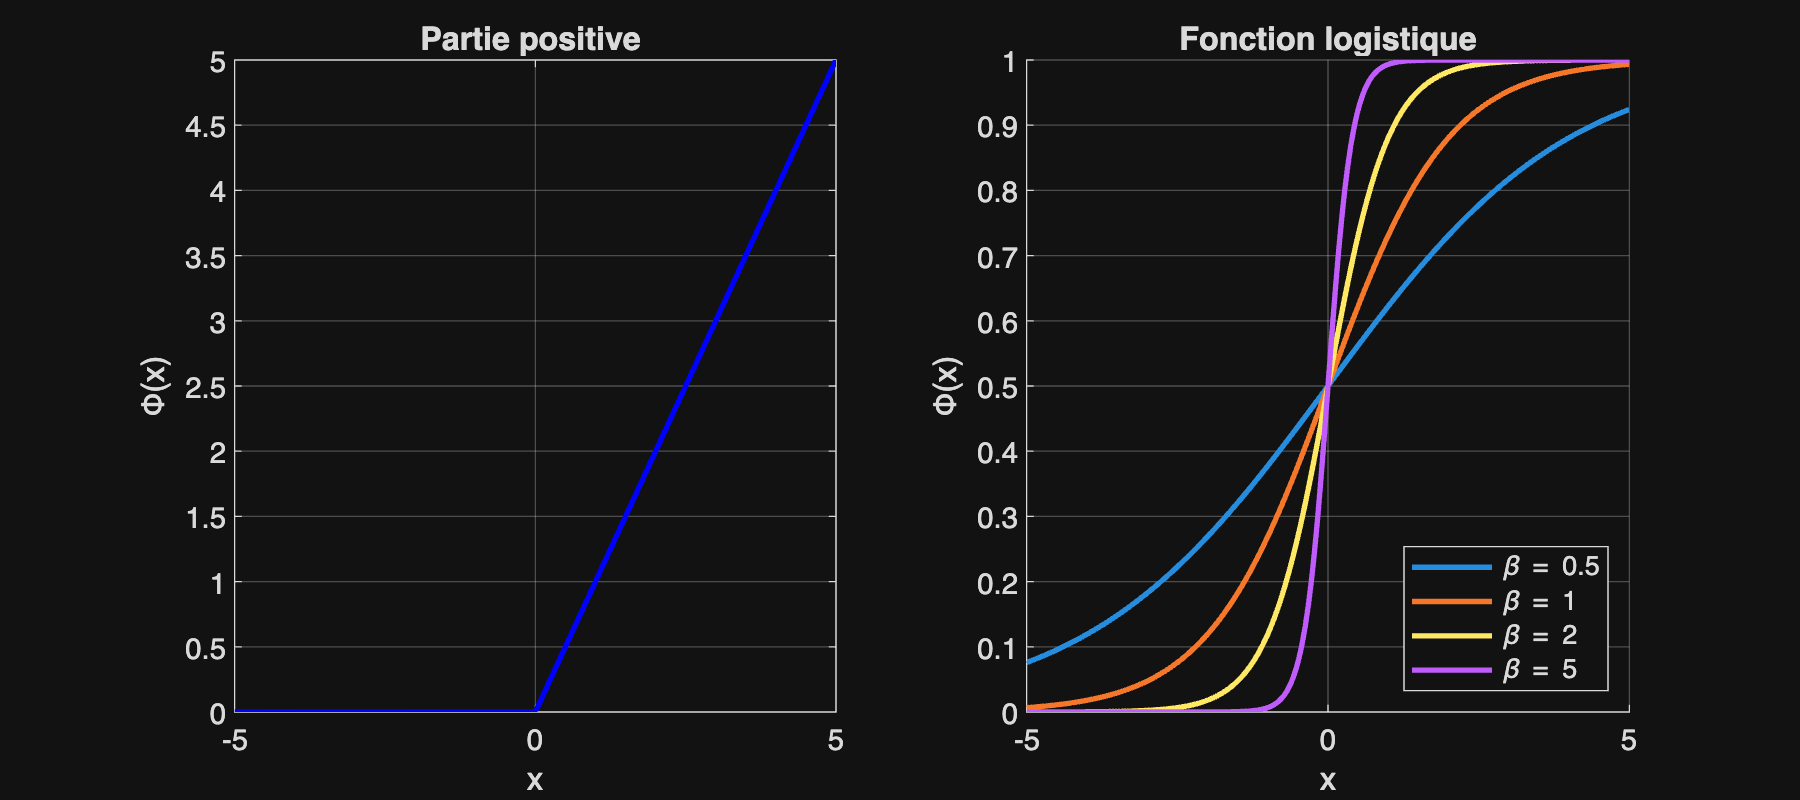

Phi_m = @(x) max(x, 0);
Phi_logistique = @(x, beta) 1 ./ (1 + exp(-beta * x));


figure('Position', [100 100 900 400]);
x = linspace(-5, 5, 200);

subplot(1,2,1);
plot(x, Phi_m(x), 'b-', 'LineWidth', 2);
xlabel('x', 'FontSize', 12); ylabel('\Phi(x)', 'FontSize', 12);
title('Partie positive ', 'FontSize', 14);
grid on; set(gca, 'FontSize', 11);

subplot(1,2,2);
beta_valeurs = [0.5, 1, 2, 5];
colors = lines(4);
hold on;
for i = 1:length(beta_valeurs)
    plot(x, Phi_logistique(x, beta_valeurs(i)), 'LineWidth', 2, ...
         'Color', colors(i,:), 'DisplayName', ['\beta = ' num2str(beta_valeurs(i))]);
end
xlabel('x', 'FontSize', 12); ylabel('\Phi(x)', 'FontSize', 12);
title('Fonction logistique', 'FontSize', 14);
legend('Location', 'southeast', 'FontSize', 10); 
grid on; set(gca, 'FontSize', 11);

**Observation :** Plus $\beta$ est grand, plus la transition de la fonction logistique est abrupte. Pour $\beta \to \infty$, on tend vers une fonction échelon.

## 1.2 Simulation avec excitation mutuelle

On étudie un système de 2 neurones avec une matrice de connectivité représentant une excitation mutuelle modérée.

**Paramètres :**

- $\lambda = 1$ (taux de décroissance)

- $\beta = 2$ (raideur de la logistique)

- $W=\left\lbrack \begin{array}{cc}
0 & 1\\
1 & 0
\end{array}\right\rbrack$ (excitation mutuelle)

- $B=\left\lbrack \begin{array}{c}
2\\
2
\end{array}\right\rbrack$ (stimulation externe)

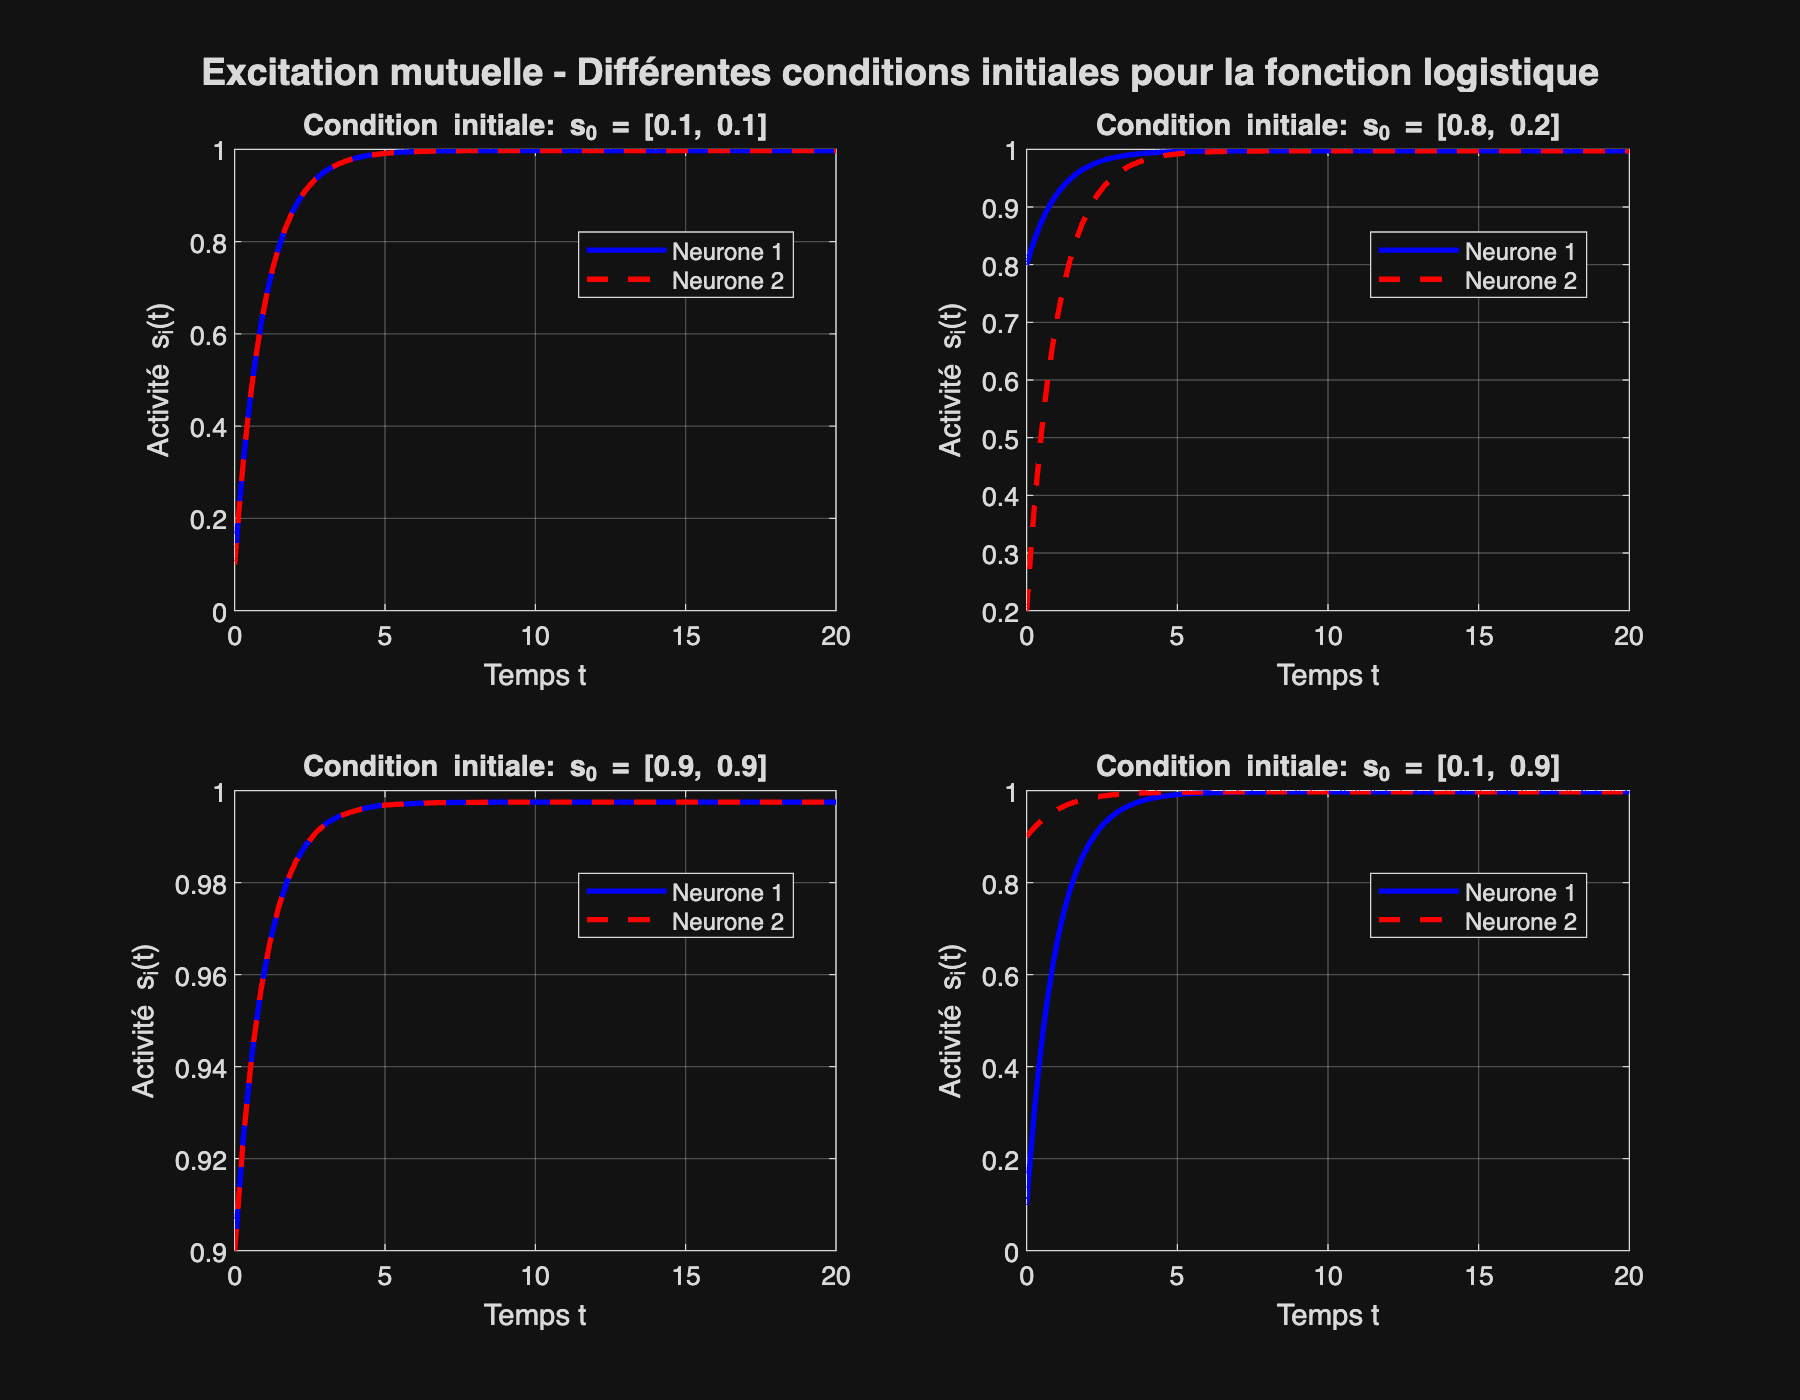

lambda = 1;
beta = 2;
Phi = @(x, beta) 1 ./ (1 + exp(-beta * x));
Phi_m = @(x) max(x, 0);

W = [0, 1; 1, 0];
B = [2; 2];

s0_liste = {[0.1; 0.1], [0.8; 0.2], [0.9; 0.9], [0.1; 0.9]};
tspan = [0, 20];

figure('Position', [100 100 900 700]);
for k = 1:length(s0_liste)
    s0 = s0_liste{k};
    [t_l, s_l] = ode45(@(t,s) -lambda*s + Phi(W*s + B,beta), tspan, s0);
    [t_m,s_m] = ode45(@(t,s) -lambda*s + Phi_m(W*s + B), tspan, s0);

    subplot(2,2,k);
    plot(t_l, s_l(:,1), 'b-', 'LineWidth', 2); hold on;
    plot(t_l, s_l(:,2), 'r--', 'LineWidth', 2);
    xlabel('Temps t', 'FontSize', 11); ylabel('Activité s_i(t)', 'FontSize', 11);
    title(['Condition initiale: s_0 = [' num2str(s0(1)) ', ' num2str(s0(2)) ']'], 'FontSize', 12);
    legend('Neurone 1', 'Neurone 2', 'Location', 'best');
    grid on; set(gca, 'FontSize', 10);
    
end

sgtitle('Excitation mutuelle - Différentes conditions initiales pour la fonction logistique', 'FontSize', 14, 'FontWeight', 'bold');

**Observation :** Quelle que soit la condition initiale, les deux neurones convergent vers le même état d'équilibre stable. 

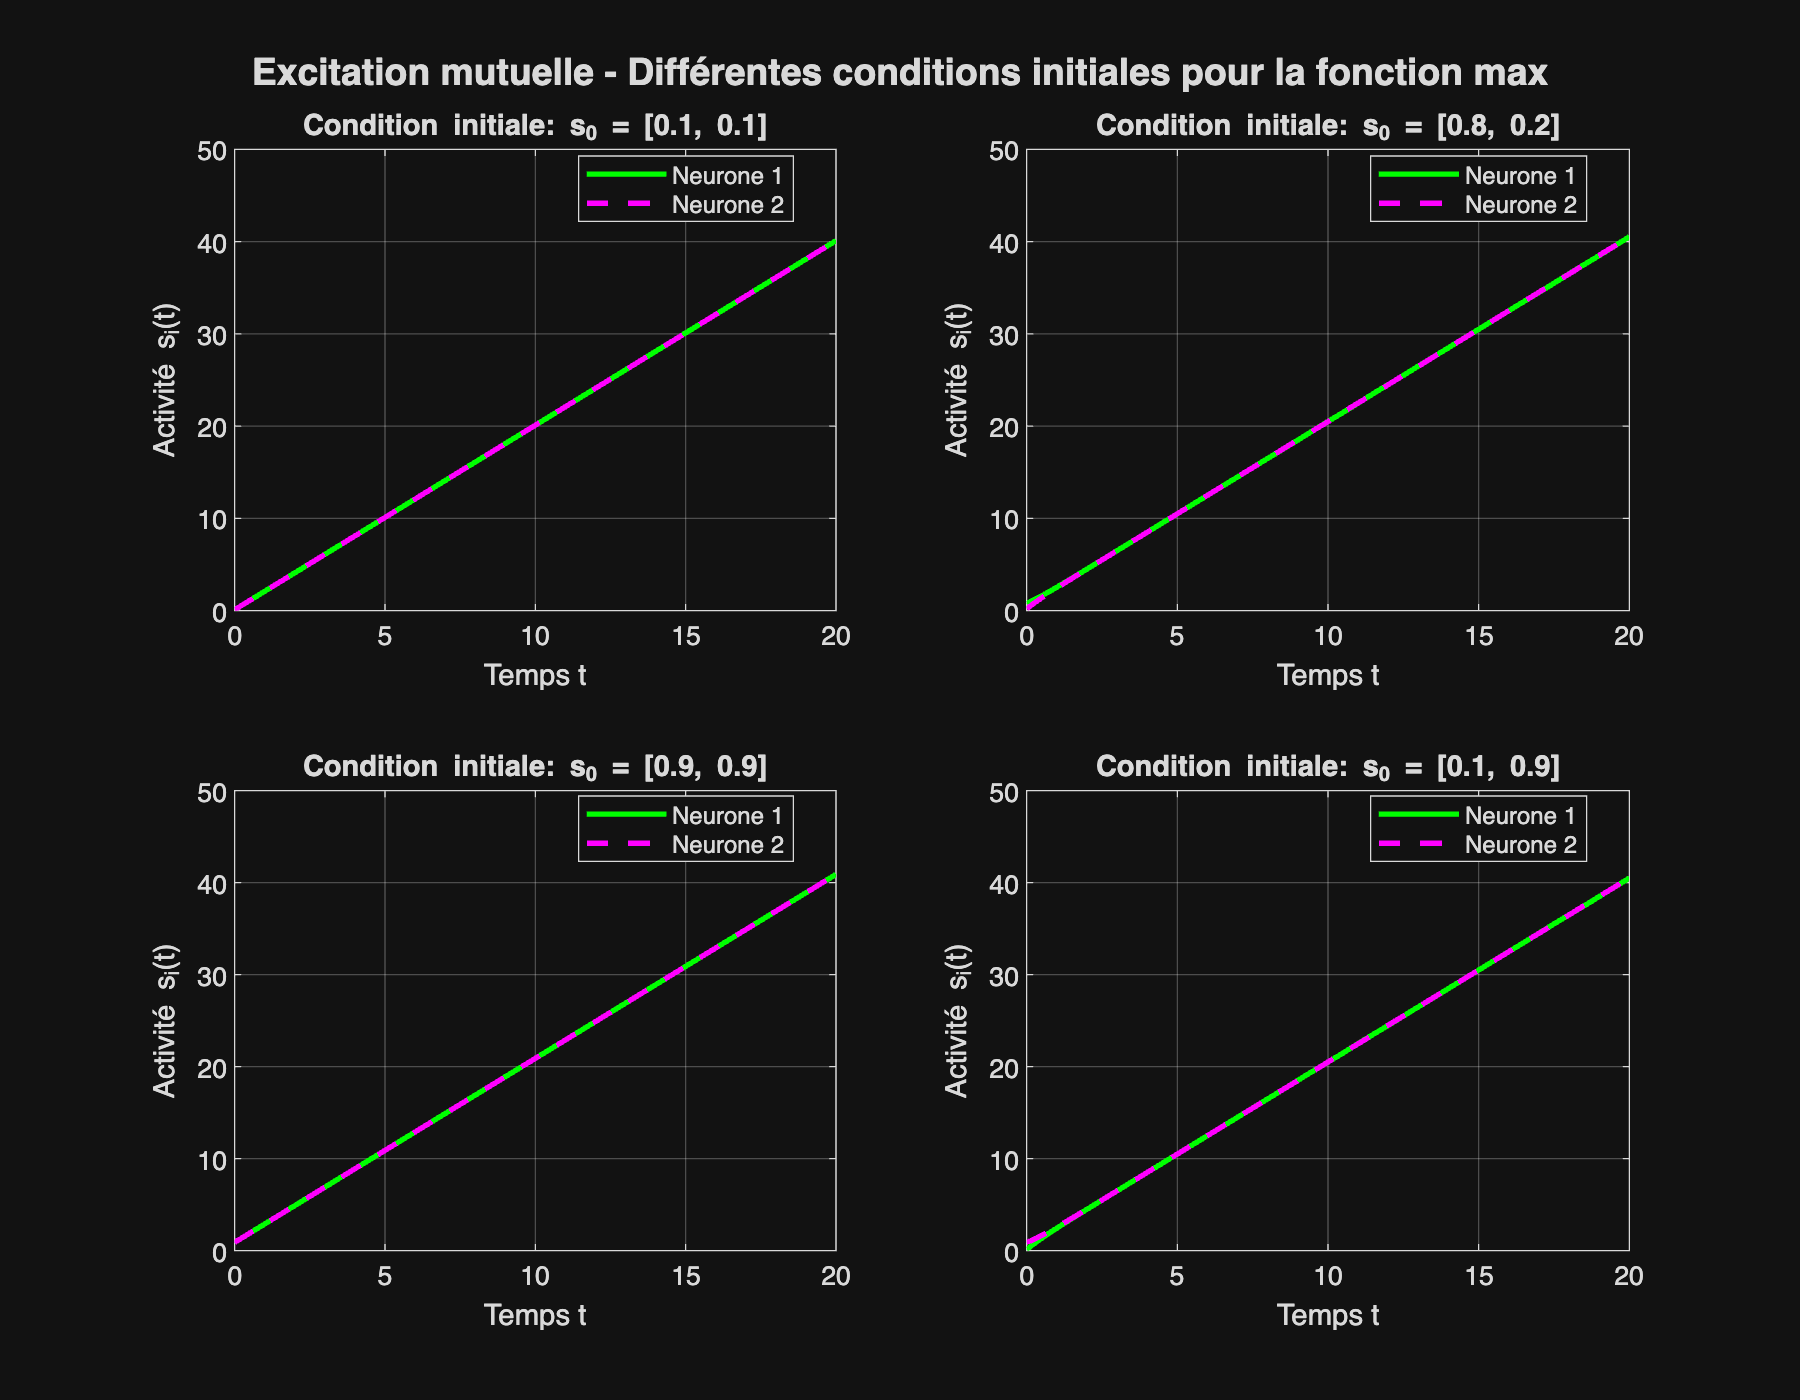

Phi = @(x, beta) 1 ./ (1 + exp(-beta * x));
Phi_m = @(x) max(x, 0);

W = [0, 1.0; 1.0, 0];
B = [2; 2];

s0_liste = {[0.1; 0.1], [0.8; 0.2], [0.9; 0.9], [0.1; 0.9]};
tspan = [0, 20];

figure('Position', [100 100 900 700]);
for k = 1:length(s0_liste)
    s0 = s0_liste{k};
    [t_l, s_l] = ode45(@(t,s) -lambda*s + Phi(W*s + B,beta), tspan, s0);
    [t_m,s_m] = ode45(@(t,s) -lambda*s + Phi_m(W*s + B), tspan, s0);

    subplot(2,2,k);
    plot(t_m, s_m(:,1), 'g-', 'LineWidth', 2); hold on;
    plot(t_m, s_m(:,2), 'm--', 'LineWidth', 2);
    xlabel('Temps t', 'FontSize', 11); ylabel('Activité s_i(t)', 'FontSize', 11);
    title(['Condition initiale: s_0 = [' num2str(s0(1)) ', ' num2str(s0(2)) ']'], 'FontSize', 12);
    legend('Neurone 1', 'Neurone 2', 'Location', 'best');
    grid on; set(gca, 'FontSize', 10);
    
end

sgtitle('Excitation mutuelle - Différentes conditions initiales pour la fonction max', 'FontSize', 14, 'FontWeight', 'bold');

**Observation :** Quelle que soit la condition initiale, les deux activités devienne égale a partir d'un certain moment et converge vers $+\infty$

## 1.3 Portrait de phase

Le portrait de phase permet de visualiser les trajectoires du système dans l'espace des états $(s_1, s_2)$.

Phi = @(x, beta) 1 ./ (1 + exp(-beta * x));

figure('Position', [100 100 600 500]);
couleurs = lines(length(s0_liste));
hold on;

for k = 1:length(s0_liste)
    s0 = s0_liste{k};
    [t, s] = ode45(@(t,s) -lambda*s + Phi(W*s + B,beta), tspan, s0);
    plot(s(:,1), s(:,2), 'LineWidth', 2, 'Color', couleurs(k,:));
    plot(s0(1), s0(2), 'o', 'MarkerSize', 12, 'MarkerFaceColor', couleurs(k,:), 'MarkerEdgeColor', 'k');
    plot(s(end,1), s(end,2), 's', 'MarkerSize', 14, 'MarkerFaceColor', couleurs(k,:), 'MarkerEdgeColor', 'k');
end


[S1, S2] = meshgrid(linspace(0, 1, 12), linspace(0, 1, 12));
dS1 = zeros(size(S1)); dS2 = zeros(size(S2));
for i = 1:numel(S1)
    s_temp = [S1(i); S2(i)];
    dsdt = -lambda * s_temp + Phi(W * s_temp + B,beta);
    dS1(i) = dsdt(1); dS2(i) = dsdt(2);
end
quiver(S1, S2, dS1, dS2, 'k', 'AutoScaleFactor', 0.5);

xlabel('s_1', 'FontSize', 12); ylabel('s_2', 'FontSize', 12);
title('Portrait de phase - Excitation mutuelle pour la fonction logistique', 'FontSize', 14);
grid on; axis equal; xlim([0 1]); ylim([0 1]);
set(gca, 'FontSize', 11);

**Légende :** Les cercles représentent les conditions initiales, les carrés représentent les états finaux (équilibres). Toutes les trajectoires convergent vers un unique point d'équilibre stable.

Phi = @(x) max(x, 0);

figure('Position', [100 100 600 500]);
couleurs = lines(length(s0_liste));
hold on;

for k = 1:length(s0_liste)
    s0 = s0_liste{k};
    [t, s] = ode45(@(t,s) -lambda*s + Phi(W*s + B), tspan, s0);
    plot(s(:,1), s(:,2), 'LineWidth', 2, 'Color', couleurs(k,:));
    plot(s0(1), s0(2), 'o', 'MarkerSize', 12, 'MarkerFaceColor', couleurs(k,:), 'MarkerEdgeColor', 'k');
    plot(s(end,1), s(end,2), 's', 'MarkerSize', 14, 'MarkerFaceColor', couleurs(k,:), 'MarkerEdgeColor', 'k');
end


[S1, S2] = meshgrid(linspace(0, 1, 12), linspace(0, 1, 12));
dS1 = zeros(size(S1)); dS2 = zeros(size(S2));
for i = 1:numel(S1)
    s_temp = [S1(i); S2(i)];
    dsdt = -lambda * s_temp + Phi(W * s_temp + B);
    dS1(i) = dsdt(1); dS2(i) = dsdt(2);
end
quiver(S1, S2, dS1, dS2, 'k', 'AutoScaleFactor', 0.5);

xlabel('s_1', 'FontSize', 12); ylabel('s_2', 'FontSize', 12);
title('Portrait de phase - Excitation mutuelle pour la fonction max', 'FontSize', 14);
grid on; axis equal; xlim([0 1]); ylim([0 1]);
set(gca, 'FontSize', 11);

**Légende :** Les cercles représentent les conditions initiales, les carrés représentent les états finaux (équilibres). Toutes les trajectoires convergent vers $+\infty$ qu'elle que soit les conditions initiales

## 1.4 Exploration de différentes configurations

On explore maintenant différentes configurations de la matrice de connectivité pour observer les comportements variés du système.

### **Pour la fonction Logistique:**

**1) Le vaiqueur prend tout :**

**Paramètres :**

- 
$$\lambda = 1$$
 

- 
$$\beta = 2$$
 

- 
$$W=\left\lbrack \begin{array}{cc}
0 & -4\\
-4 & 0
\end{array}\right\rbrack$$
 

- 
$$B=\left\lbrack \begin{array}{c}
2\\
2
\end{array}\right\rbrack$$
 

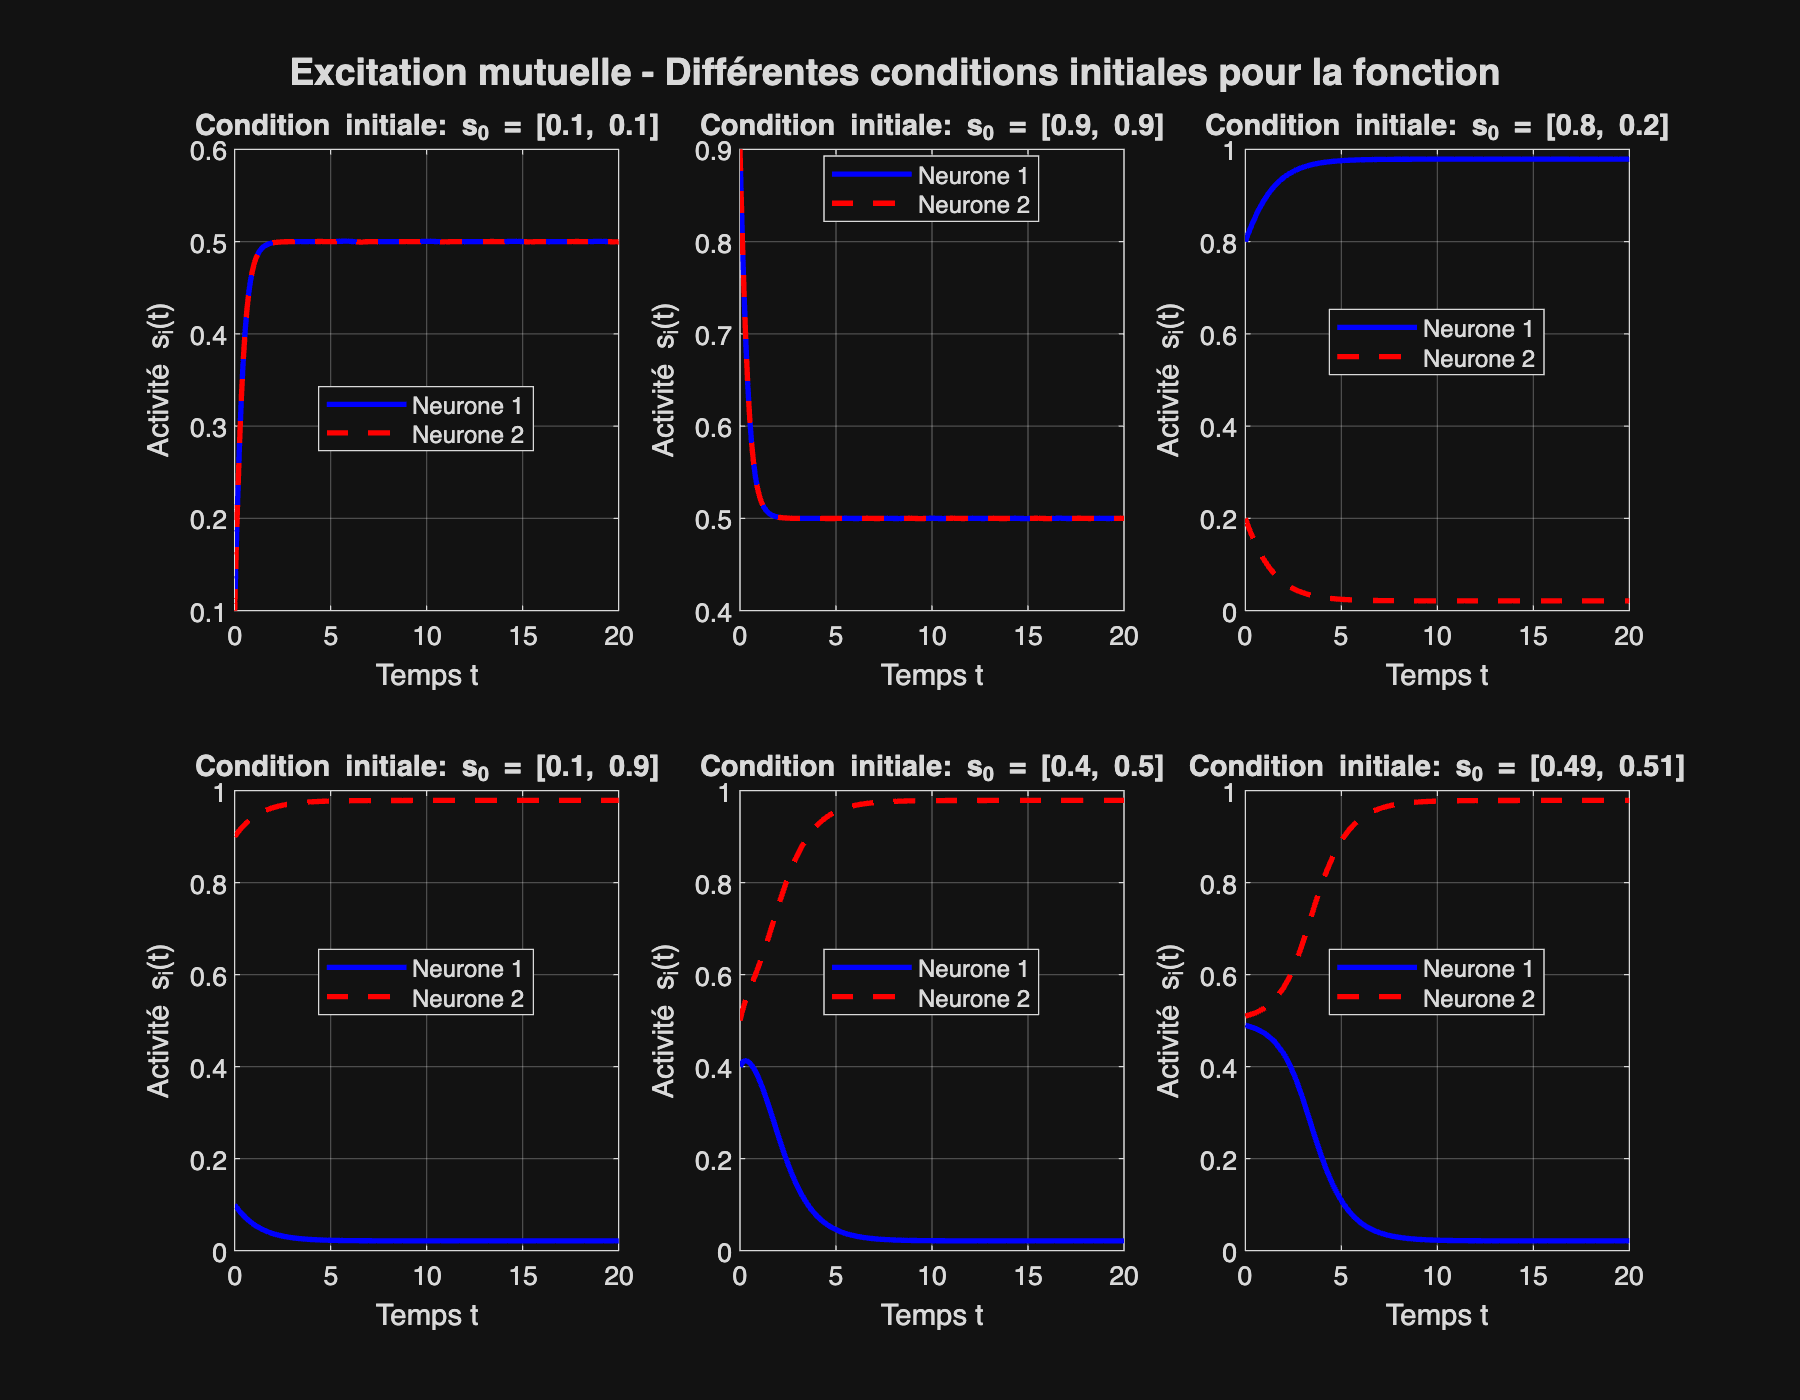

Phi = @(x, beta) 1 ./ (1 + exp(-beta * x));
W = [0, -4; -4, 0];
B = [2; 2];
lambda=1;
beta = 2;

s0_liste = {[0.1; 0.1],[0.9; 0.9], [0.8; 0.2],  [0.1; 0.9],[0.4,0.5],[0.49,0.51]};
tspan = [0, 20];

figure('Position', [100 100 900 700]);
for k = 1:length(s0_liste)
    s0 = s0_liste{k};
    [t_l, s_l] = ode45(@(t,s) -lambda*s + Phi(W*s + B,beta), tspan, s0);
    

    subplot(2,3,k);
    plot(t_l, s_l(:,1), 'b-', 'LineWidth', 2); hold on;
    plot(t_l, s_l(:,2), 'r--', 'LineWidth', 2);
    xlabel('Temps t', 'FontSize', 11); ylabel('Activité s_i(t)', 'FontSize', 11);
    title(['Condition initiale: s_0 = [' num2str(s0(1)) ', ' num2str(s0(2)) ']'], 'FontSize', 12);
    legend('Neurone 1', 'Neurone 2', 'Location', 'best');
    grid on; set(gca, 'FontSize', 10);
    
end

sgtitle('Excitation mutuelle - Différentes conditions initiales pour la fonction ', 'FontSize', 14, 'FontWeight', 'bold');

Pour $B=\left\lbrack \begin{array}{c}
3\\
3
\end{array}\right\rbrack$ 

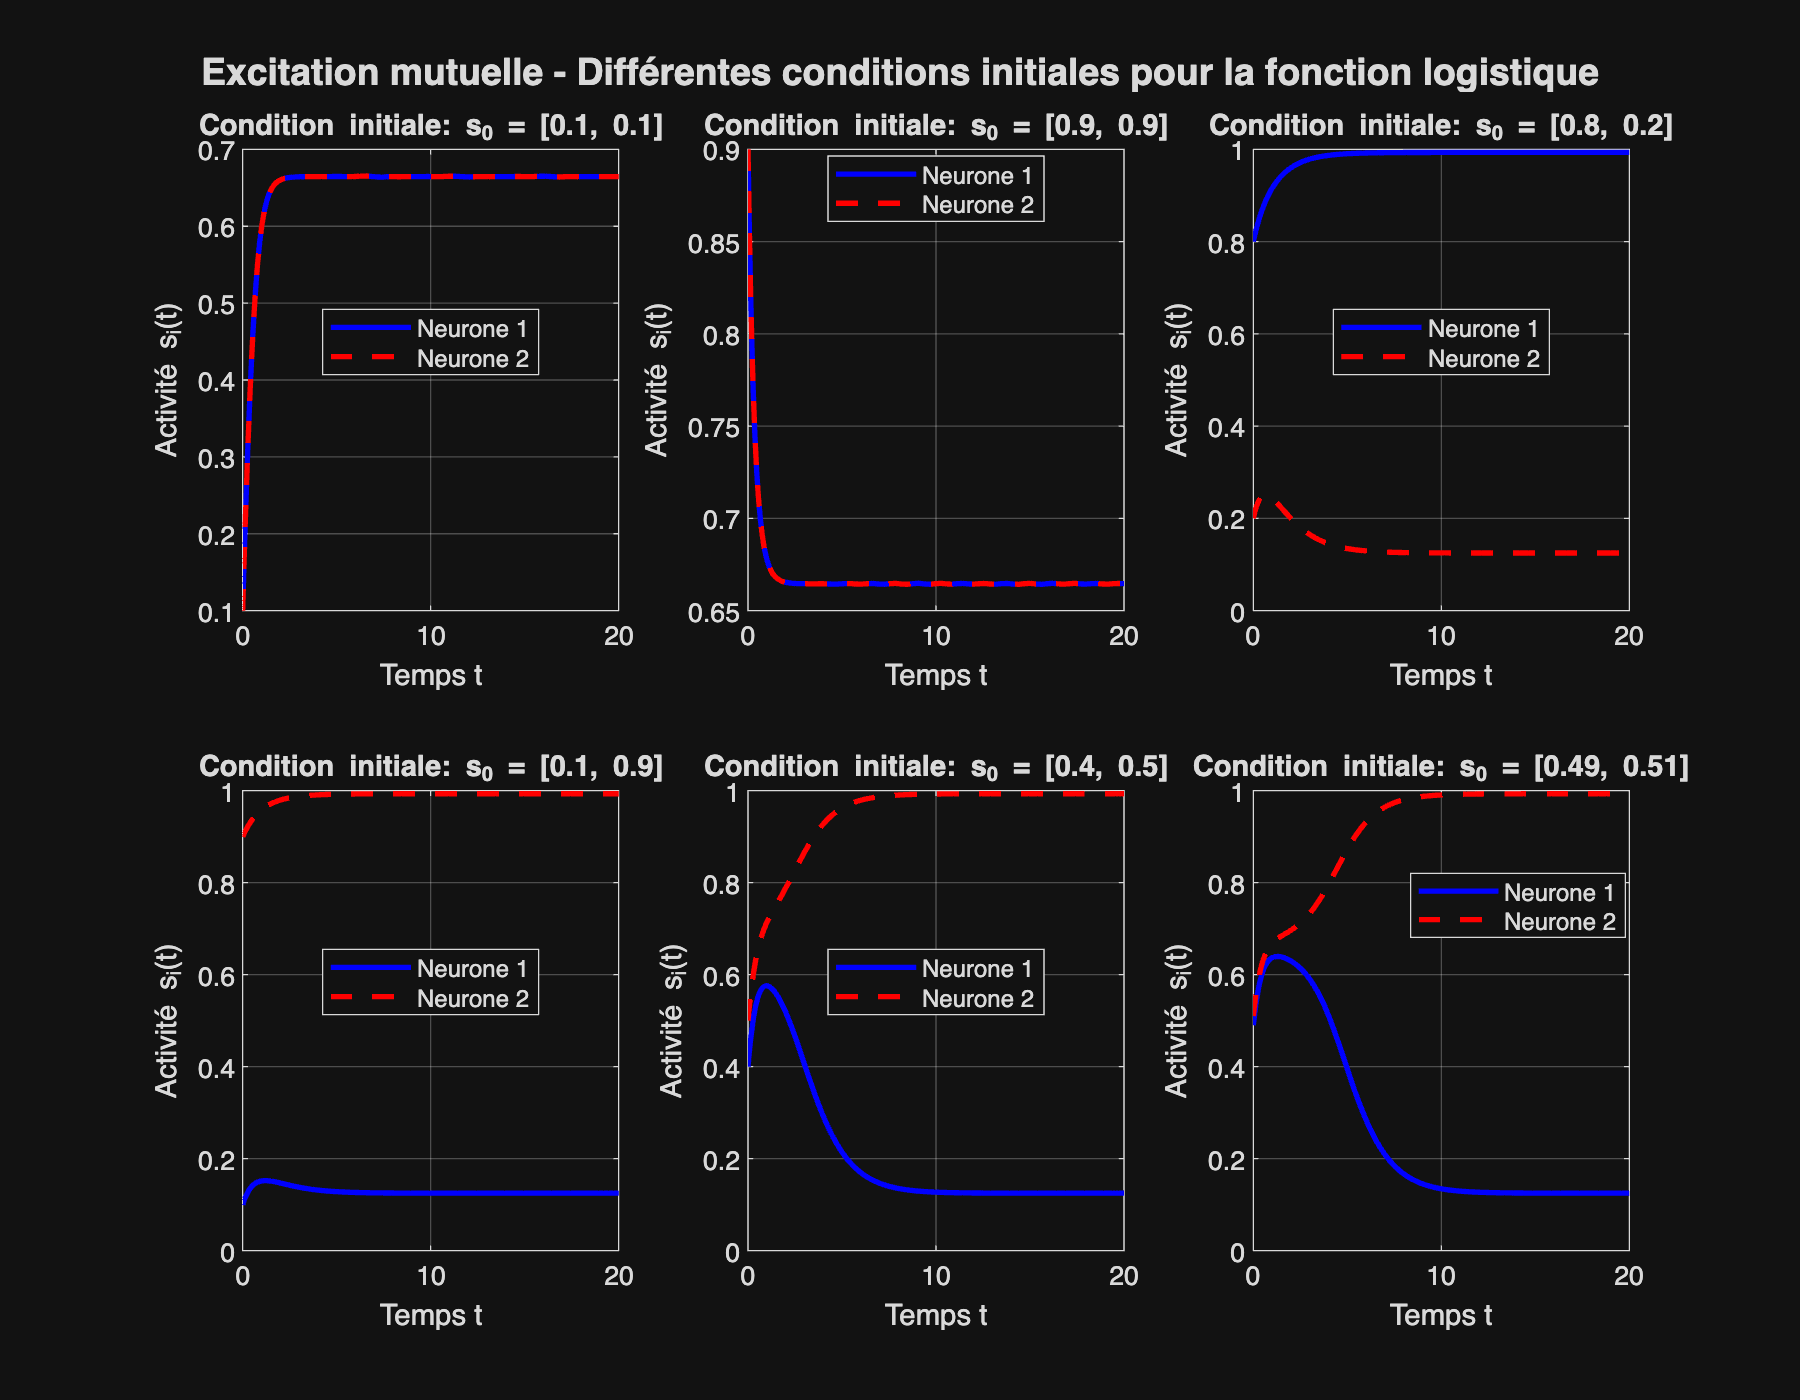

Phi = @(x, beta) 1 ./ (1 + exp(-beta * x));
W = [0, -4; -4, 0];
B = [3; 3];


s0_liste = {[0.1; 0.1],[0.9; 0.9], [0.8; 0.2],  [0.1; 0.9],[0.4,0.5],[0.49,0.51]};
tspan = [0, 20];

figure('Position', [100 100 900 700]);
for k = 1:length(s0_liste)
    s0 = s0_liste{k};
    [t_l, s_l] = ode45(@(t,s) -lambda*s + Phi(W*s + B,beta), tspan, s0);
    

    subplot(2,3,k);
    plot(t_l, s_l(:,1), 'b-', 'LineWidth', 2); hold on;
    plot(t_l, s_l(:,2), 'r--', 'LineWidth', 2);
    xlabel('Temps t', 'FontSize', 11); ylabel('Activité s_i(t)', 'FontSize', 11);
    title(['Condition initiale: s_0 = [' num2str(s0(1)) ', ' num2str(s0(2)) ']'], 'FontSize', 12);
    legend('Neurone 1', 'Neurone 2', 'Location', 'best');
    grid on; set(gca, 'FontSize', 10);
    
end

sgtitle('Excitation mutuelle - Différentes conditions initiales pour la fonction logistique', 'FontSize', 14, 'FontWeight', 'bold');

Pour $B=\left\lbrack \begin{array}{c}
4\\
4
\end{array}\right\rbrack$ 

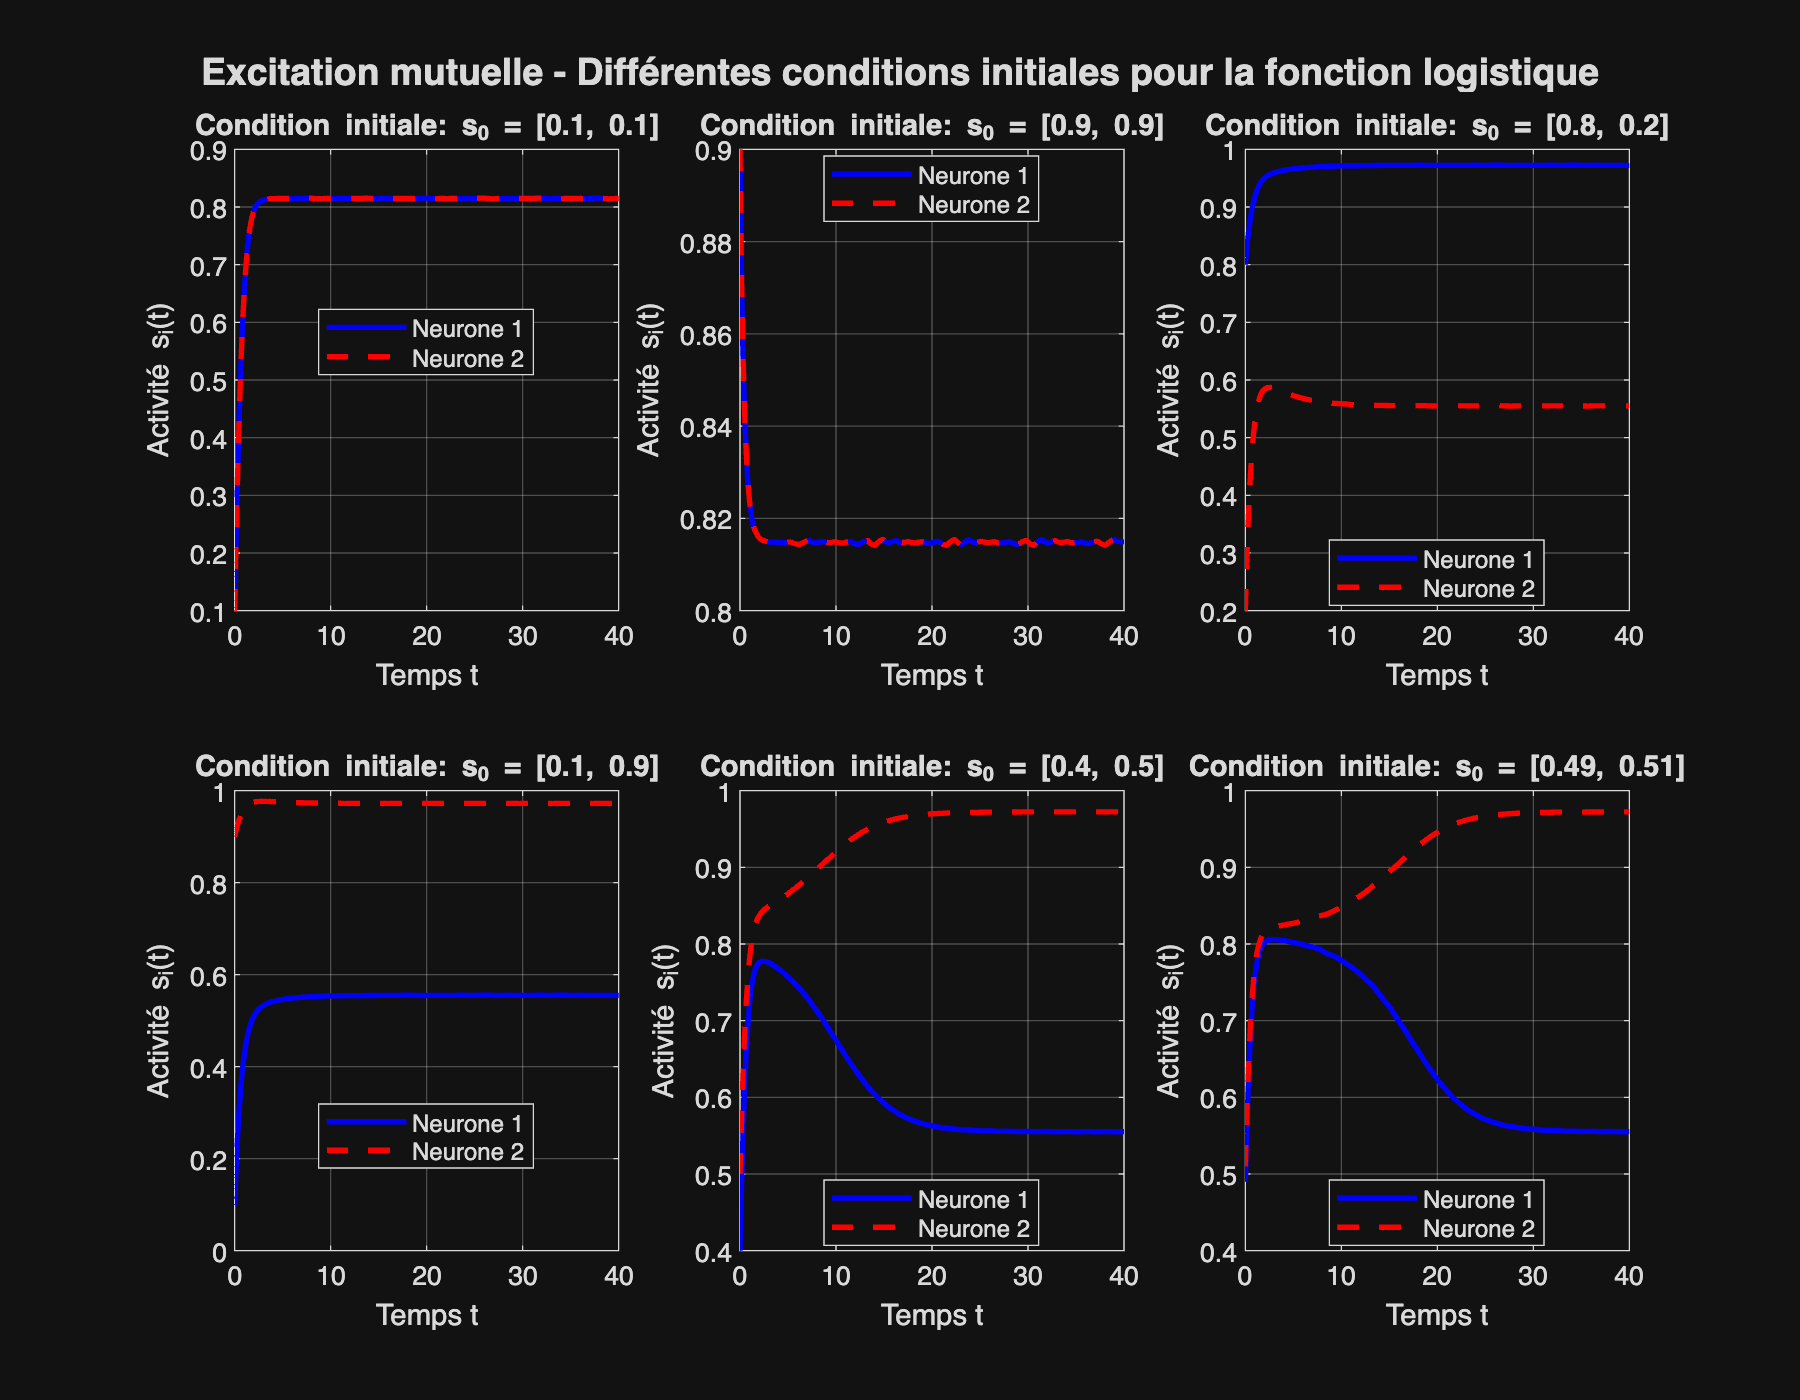

Phi = @(x, beta) 1 ./ (1 + exp(-beta * x));
W = [0, -4; -4, 0];
B = [4; 4];


s0_liste = {[0.1; 0.1],[0.9; 0.9], [0.8; 0.2],  [0.1; 0.9],[0.4,0.5],[0.49,0.51]};
tspan = [0, 40];

figure('Position', [100 100 900 700]);
for k = 1:length(s0_liste)
    s0 = s0_liste{k};
    [t_l, s_l] = ode45(@(t,s) -lambda*s + Phi(W*s + B,beta), tspan, s0);

    subplot(2,3,k);
    plot(t_l, s_l(:,1), 'b-', 'LineWidth', 2); hold on;
    plot(t_l, s_l(:,2), 'r--', 'LineWidth', 2);
    xlabel('Temps t', 'FontSize', 11); ylabel('Activité s_i(t)', 'FontSize', 11);
    title(['Condition initiale: s_0 = [' num2str(s0(1)) ', ' num2str(s0(2)) ']'], 'FontSize', 12);
    legend('Neurone 1', 'Neurone 2', 'Location', 'best');
    grid on; set(gca, 'FontSize', 10);
    
end

sgtitle('Excitation mutuelle - Différentes conditions initiales pour la fonction logistique', 'FontSize', 14, 'FontWeight', 'bold');

**Observation:** On voit que si on donne la même condition initiale au deux activité elles converge vers la même valeur.

                        Et si à l'origine l'activité 1 est plus grande que l'activité 2 alors l'activité 1 converge vers une valeur supérieur a celle de l'activité 2 l'écart entre les deux valeur diminu quand B augmente

**2) Éxitation asymétrique :**

**Paramètres :**

- $\lambda = 1$ (taux de décroissance)

- $\beta = 2$ (raideur de la logistique)

- $W=\left\lbrack \begin{array}{cc}
0 & -2\\
-10 & 0
\end{array}\right\rbrack$ (excitation mutuelle)

- $B=\left\lbrack \begin{array}{c}
2\\
2
\end{array}\right\rbrack$ (stimulation externe)

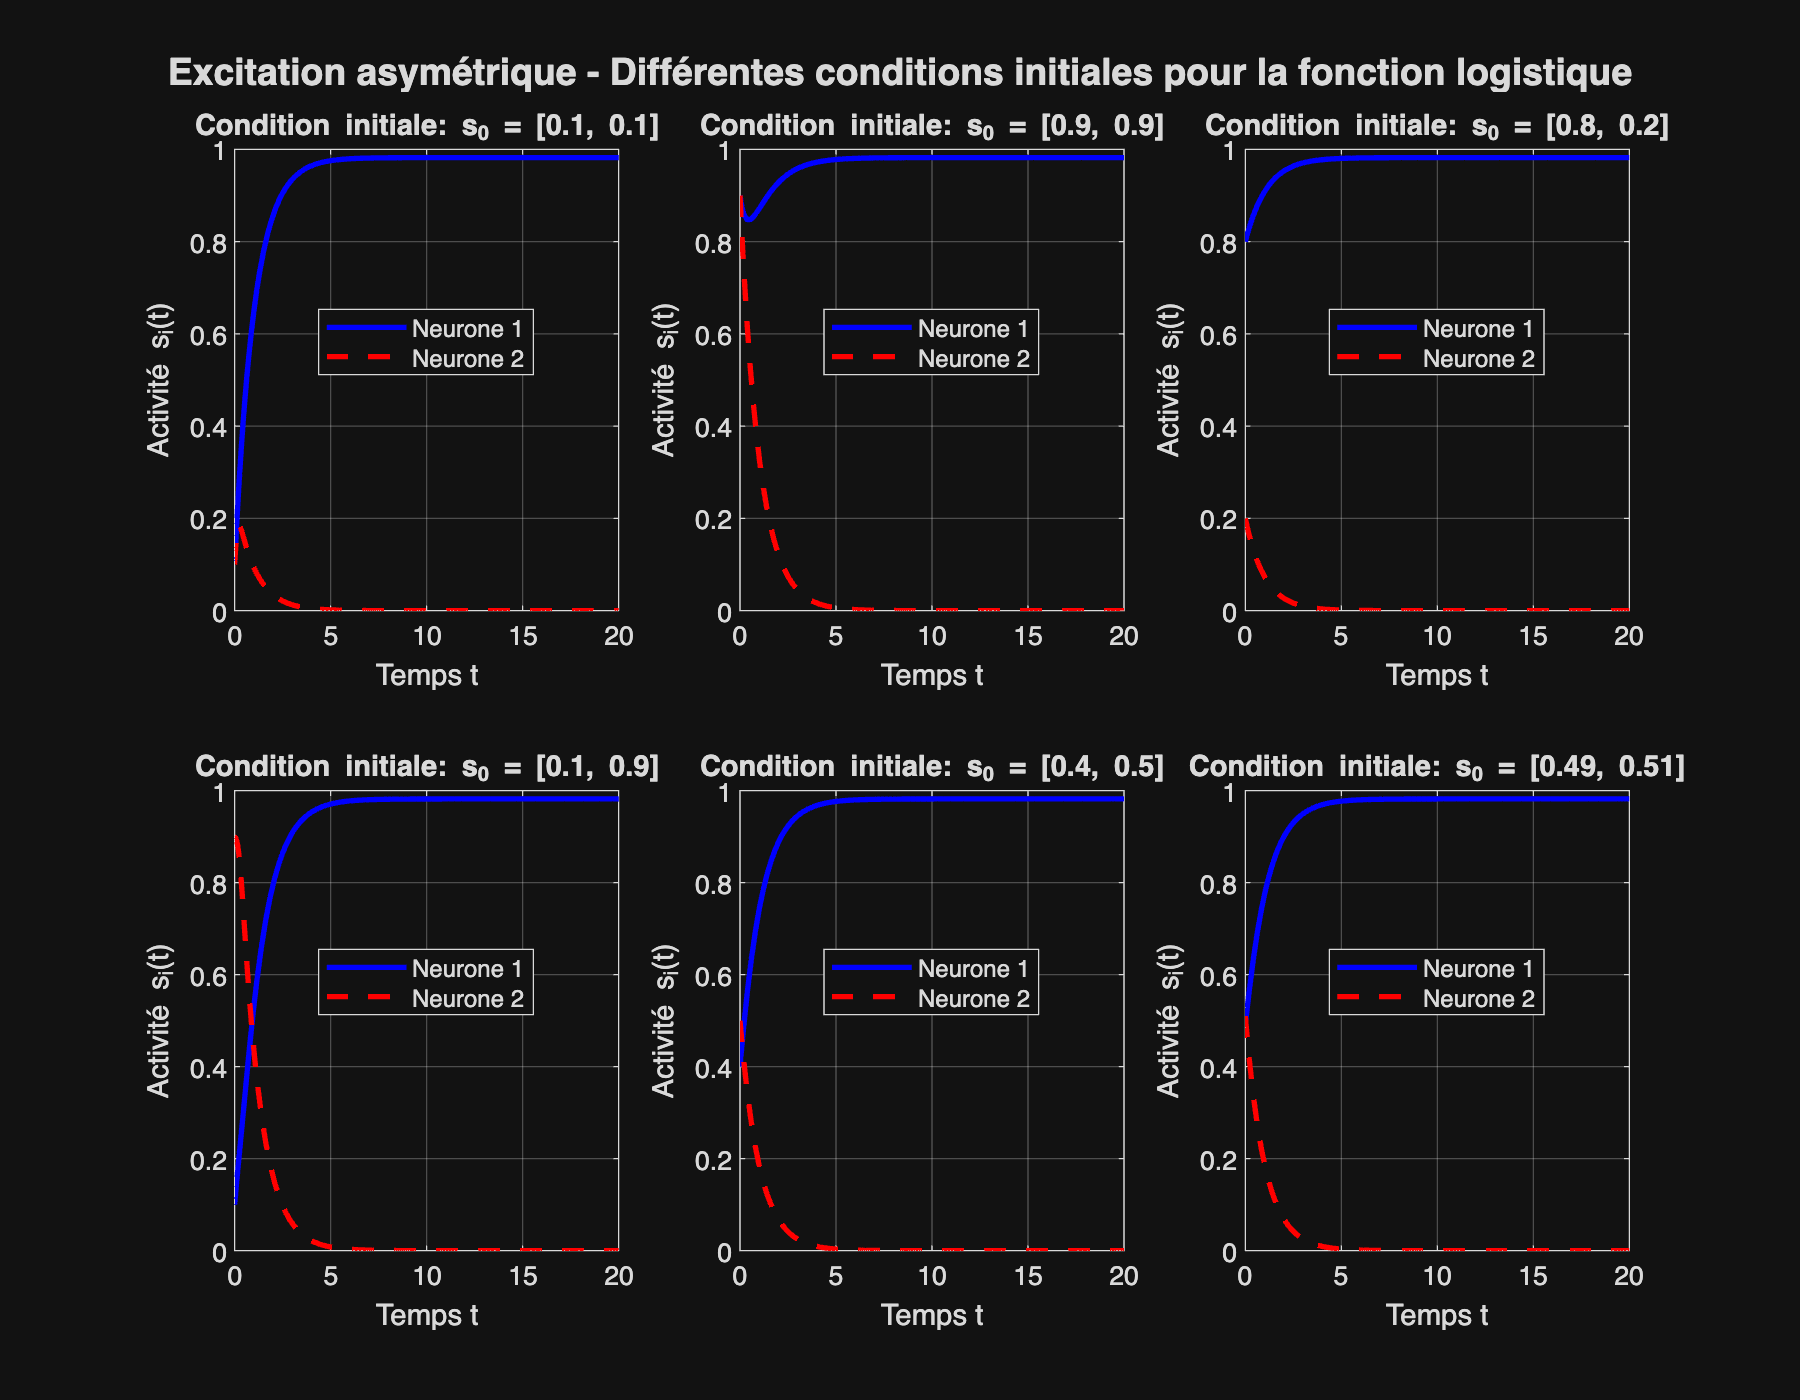

Phi = @(x, beta) 1 ./ (1 + exp(-beta * x));
W = [0,-2; -10, 0];
B = [2; 2];
lambda=1;

s0_liste = {[0.1; 0.1],[0.9; 0.9], [0.8; 0.2],  [0.1; 0.9],[0.4,0.5],[0.49,0.51]};
tspan = [0, 20];

figure('Position', [100 100 900 700]);
for k = 1:length(s0_liste)
    s0 = s0_liste{k};
    [t_l, s_l] = ode45(@(t,s) -lambda*s + Phi(W*s + B,beta), tspan, s0);
   

    subplot(2,3,k);
    plot(t_l, s_l(:,1), 'b-', 'LineWidth', 2); hold on;
    plot(t_l, s_l(:,2), 'r--', 'LineWidth', 2);
    xlabel('Temps t', 'FontSize', 11); ylabel('Activité s_i(t)', 'FontSize', 11);
    title(['Condition initiale: s_0 = [' num2str(s0(1)) ', ' num2str(s0(2)) ']'], 'FontSize', 12);
    legend('Neurone 1', 'Neurone 2', 'Location', 'best');
    grid on; set(gca, 'FontSize', 10);
    
end

sgtitle('Excitation asymétrique - Différentes conditions initiales pour la fonction logistique', 'FontSize', 14, 'FontWeight', 'bold');

Pour $B=\left\lbrack \begin{array}{c}
10\\
10
\end{array}\right\rbrack$ 

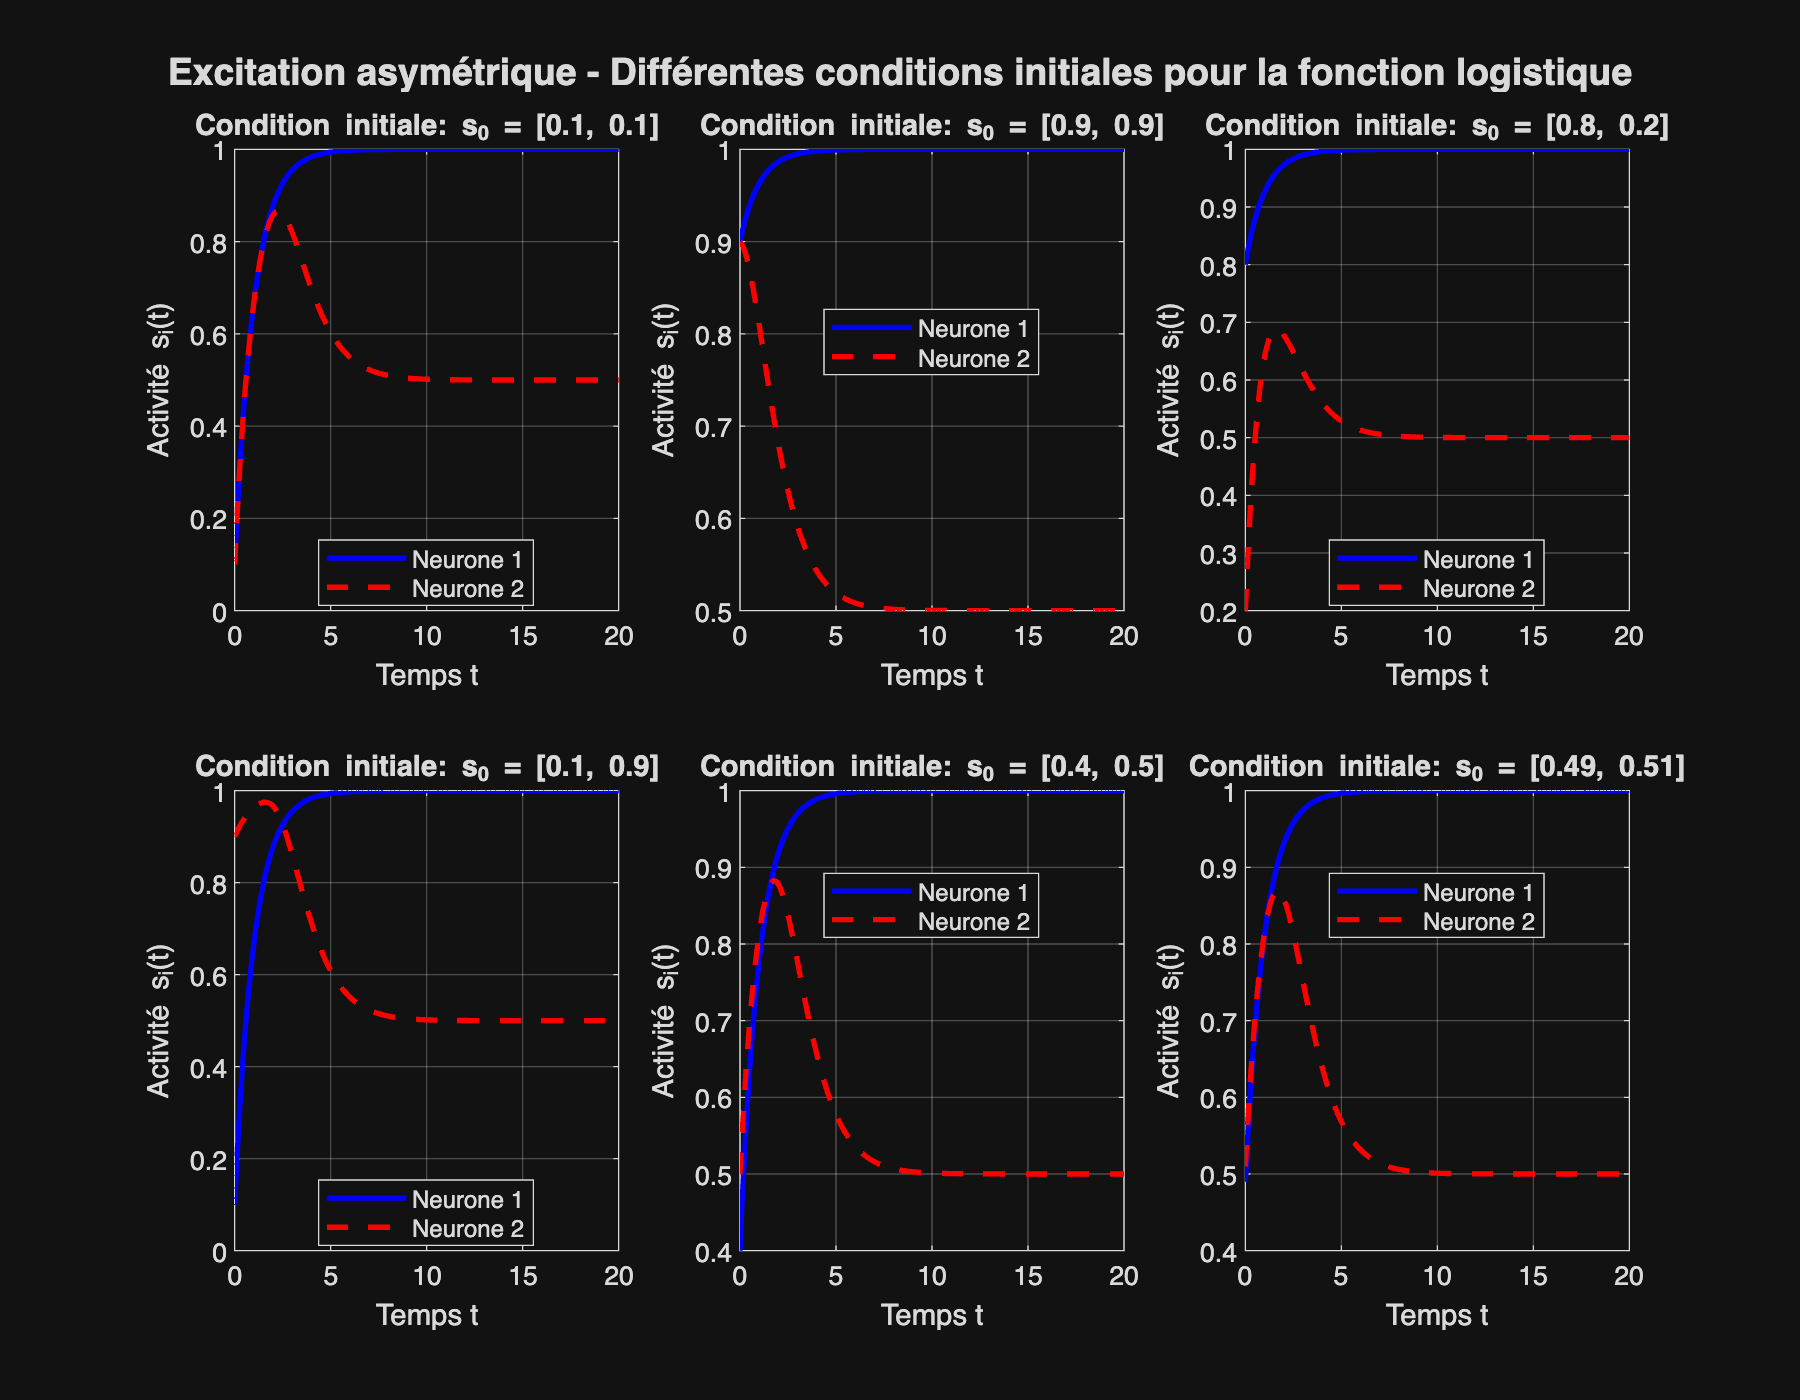

Phi = @(x, beta) 1 ./ (1 + exp(-beta * x));
W = [0,-2; -10, 0];
B = [10; 10];


s0_liste = {[0.1; 0.1],[0.9; 0.9], [0.8; 0.2],  [0.1; 0.9],[0.4,0.5],[0.49,0.51]};
tspan = [0, 20];

figure('Position', [100 100 900 700]);
for k = 1:length(s0_liste)
    s0 = s0_liste{k};
    [t_l, s_l] = ode45(@(t,s) -lambda*s + Phi(W*s + B,beta), tspan, s0);
   

    subplot(2,3,k);
    plot(t_l, s_l(:,1), 'b-', 'LineWidth', 2); hold on;
    plot(t_l, s_l(:,2), 'r--', 'LineWidth', 2);
    xlabel('Temps t', 'FontSize', 11); ylabel('Activité s_i(t)', 'FontSize', 11);
    title(['Condition initiale: s_0 = [' num2str(s0(1)) ', ' num2str(s0(2)) ']'], 'FontSize', 12);
    legend('Neurone 1', 'Neurone 2', 'Location', 'best');
    grid on; set(gca, 'FontSize', 10);
    
end

sgtitle('Excitation asymétrique - Différentes conditions initiales pour la fonction logistique', 'FontSize', 14, 'FontWeight', 'bold');

**Observation: **On voit dans ce cas ou on a une asymétrie que peux importe les condition initiale le neurone 1 converge vers 1 est le neurone 2 vers 0, si on augmente B alors le neurone 2 ne converge plus vers 0 mais vers une valeur non nul

**3) Une action positive et une action négative un neurone exitateur est un neurone inibiteur :**

**Paramètres :**

- 
$$\lambda = 1$$
 

- 
$$\beta = 2$$
 

- 
$$W=\left\lbrack \begin{array}{cc}
0 & -4\\
4 & 0
\end{array}\right\rbrack$$
 

- 
$$B=\left\lbrack \begin{array}{c}
2\\
2
\end{array}\right\rbrack$$
 

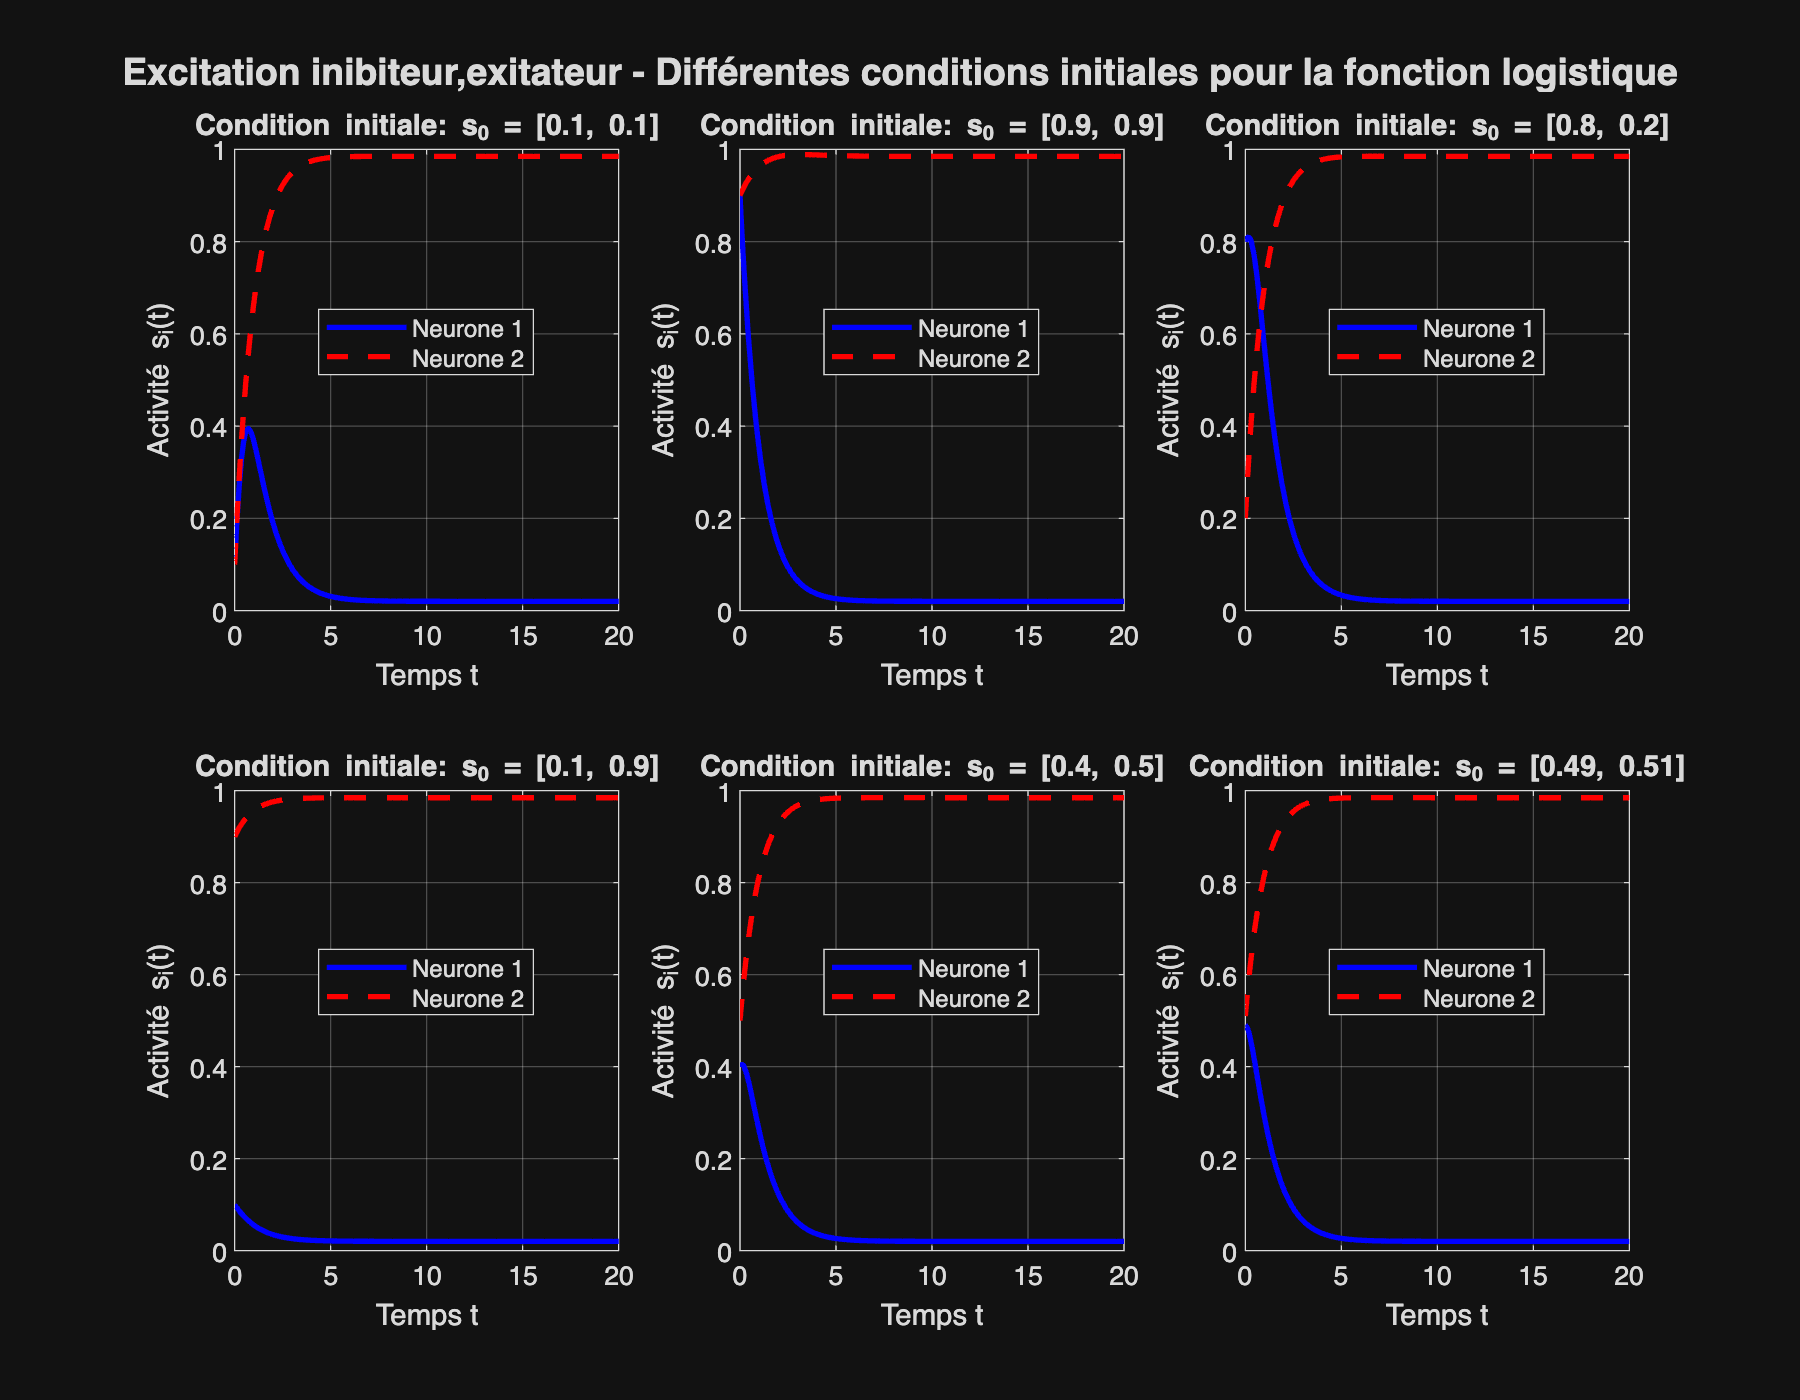

Phi = @(x, beta) 1 ./ (1 + exp(-beta * x));
W = [0,-4; 4, 0];
B = [2; 2];


s0_liste = {[0.1; 0.1],[0.9; 0.9], [0.8; 0.2],  [0.1; 0.9],[0.4,0.5],[0.49,0.51]};
tspan = [0, 20];

figure('Position', [100 100 900 700]);
for k = 1:length(s0_liste)
    s0 = s0_liste{k};
    [t_l, s_l] = ode45(@(t,s) -lambda*s + Phi(W*s + B,beta), tspan, s0);
   

    subplot(2,3,k);
    plot(t_l, s_l(:,1), 'b-', 'LineWidth', 2); hold on;
    plot(t_l, s_l(:,2), 'r--', 'LineWidth', 2);
    xlabel('Temps t', 'FontSize', 11); ylabel('Activité s_i(t)', 'FontSize', 11);
    title(['Condition initiale: s_0 = [' num2str(s0(1)) ', ' num2str(s0(2)) ']'], 'FontSize', 12);
    legend('Neurone 1', 'Neurone 2', 'Location', 'best');
    grid on; set(gca, 'FontSize', 10);
    
end

sgtitle('Excitation inibiteur,exitateur - Différentes conditions initiales pour la fonction logistique', 'FontSize', 14, 'FontWeight', 'bold');

**Observation : **On voit ici que comme l'action de 2 sur 1 est négative est l'action de 1 sur deux est positive c'est a dire que 1 donne a 2 est 2 prend de 1 alors on a que l'activité de 2 tend vers 1 est l'activité de 1 tend vers 0

### **Pour la fonction max:**

**1) Le vaiqueur prend tout :**

**Paramètres :**

- 
$$\lambda = 1$$
 

- 
$$\beta = 2$$
 

- 
$$W=\left\lbrack \begin{array}{cc}
0 & -4\\
-4 & 0
\end{array}\right\rbrack$$
 

- 
$$B=\left\lbrack \begin{array}{c}
2\\
2
\end{array}\right\rbrack$$
 

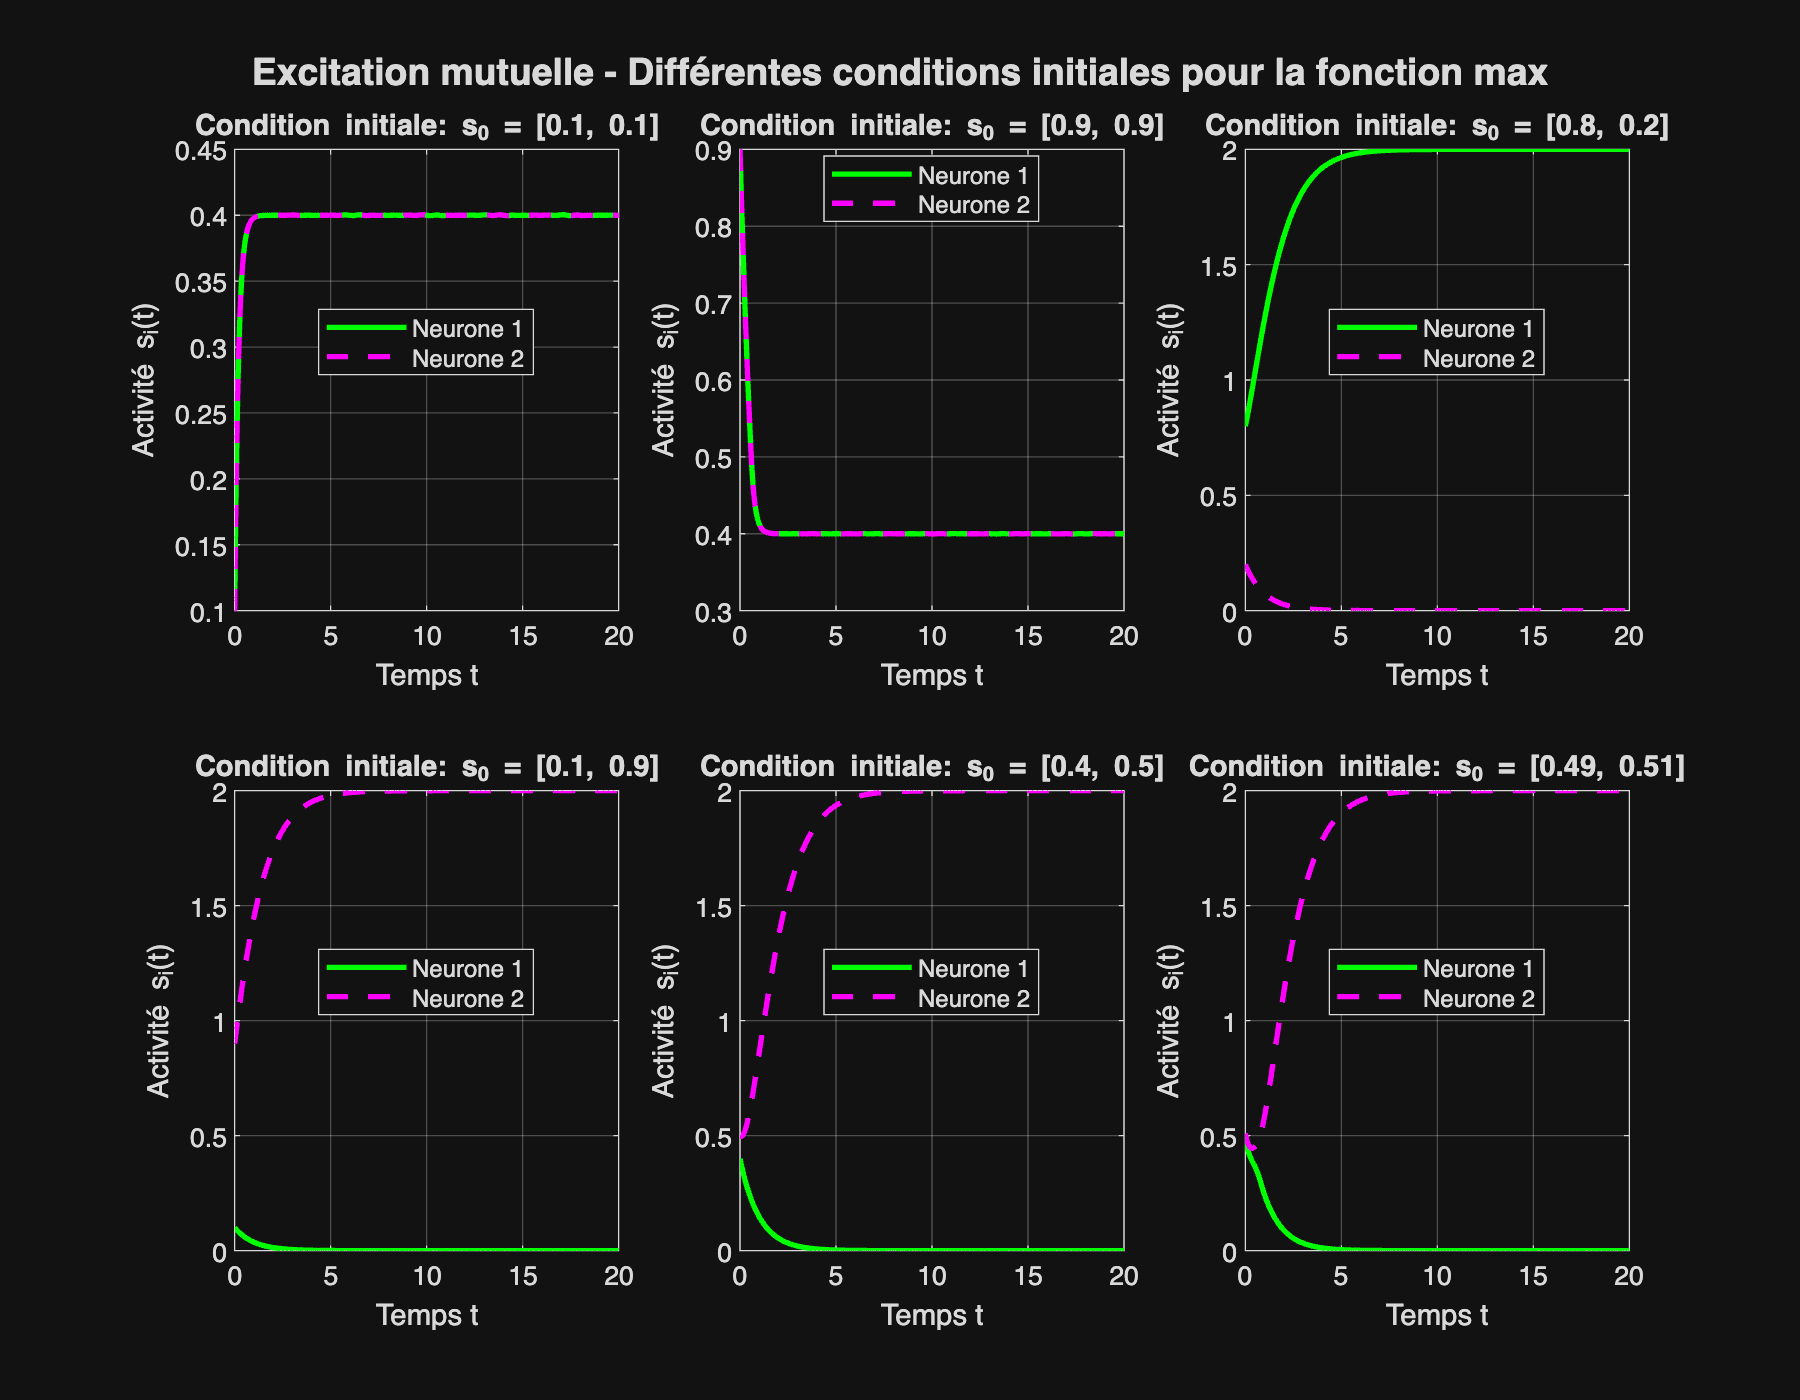

Phi = @(x) max(x, 0);
W = [0, -4; -4, 0];
B = [2; 2];


s0_liste = {[0.1; 0.1],[0.9; 0.9], [0.8; 0.2],  [0.1; 0.9],[0.4,0.5],[0.49,0.51]};
tspan = [0, 20];

figure('Position', [100 100 900 700]);
for k = 1:length(s0_liste)
    s0 = s0_liste{k};
    [t_l, s_l] = ode45(@(t,s) -lambda*s + Phi(W*s + B), tspan, s0);
    

    subplot(2,3,k);
    plot(t_l, s_l(:,1), 'g-', 'LineWidth', 2); hold on;
    plot(t_l, s_l(:,2), 'm--', 'LineWidth', 2);
    xlabel('Temps t', 'FontSize', 11); ylabel('Activité s_i(t)', 'FontSize', 11);
    title(['Condition initiale: s_0 = [' num2str(s0(1)) ', ' num2str(s0(2)) ']'], 'FontSize', 12);
    legend('Neurone 1', 'Neurone 2', 'Location', 'best');
    grid on; set(gca, 'FontSize', 10);
    
end

sgtitle('Excitation mutuelle - Différentes conditions initiales pour la fonction max', 'FontSize', 14, 'FontWeight', 'bold');

Pour $B=\left\lbrack \begin{array}{c}
3\\
3
\end{array}\right\rbrack$ 

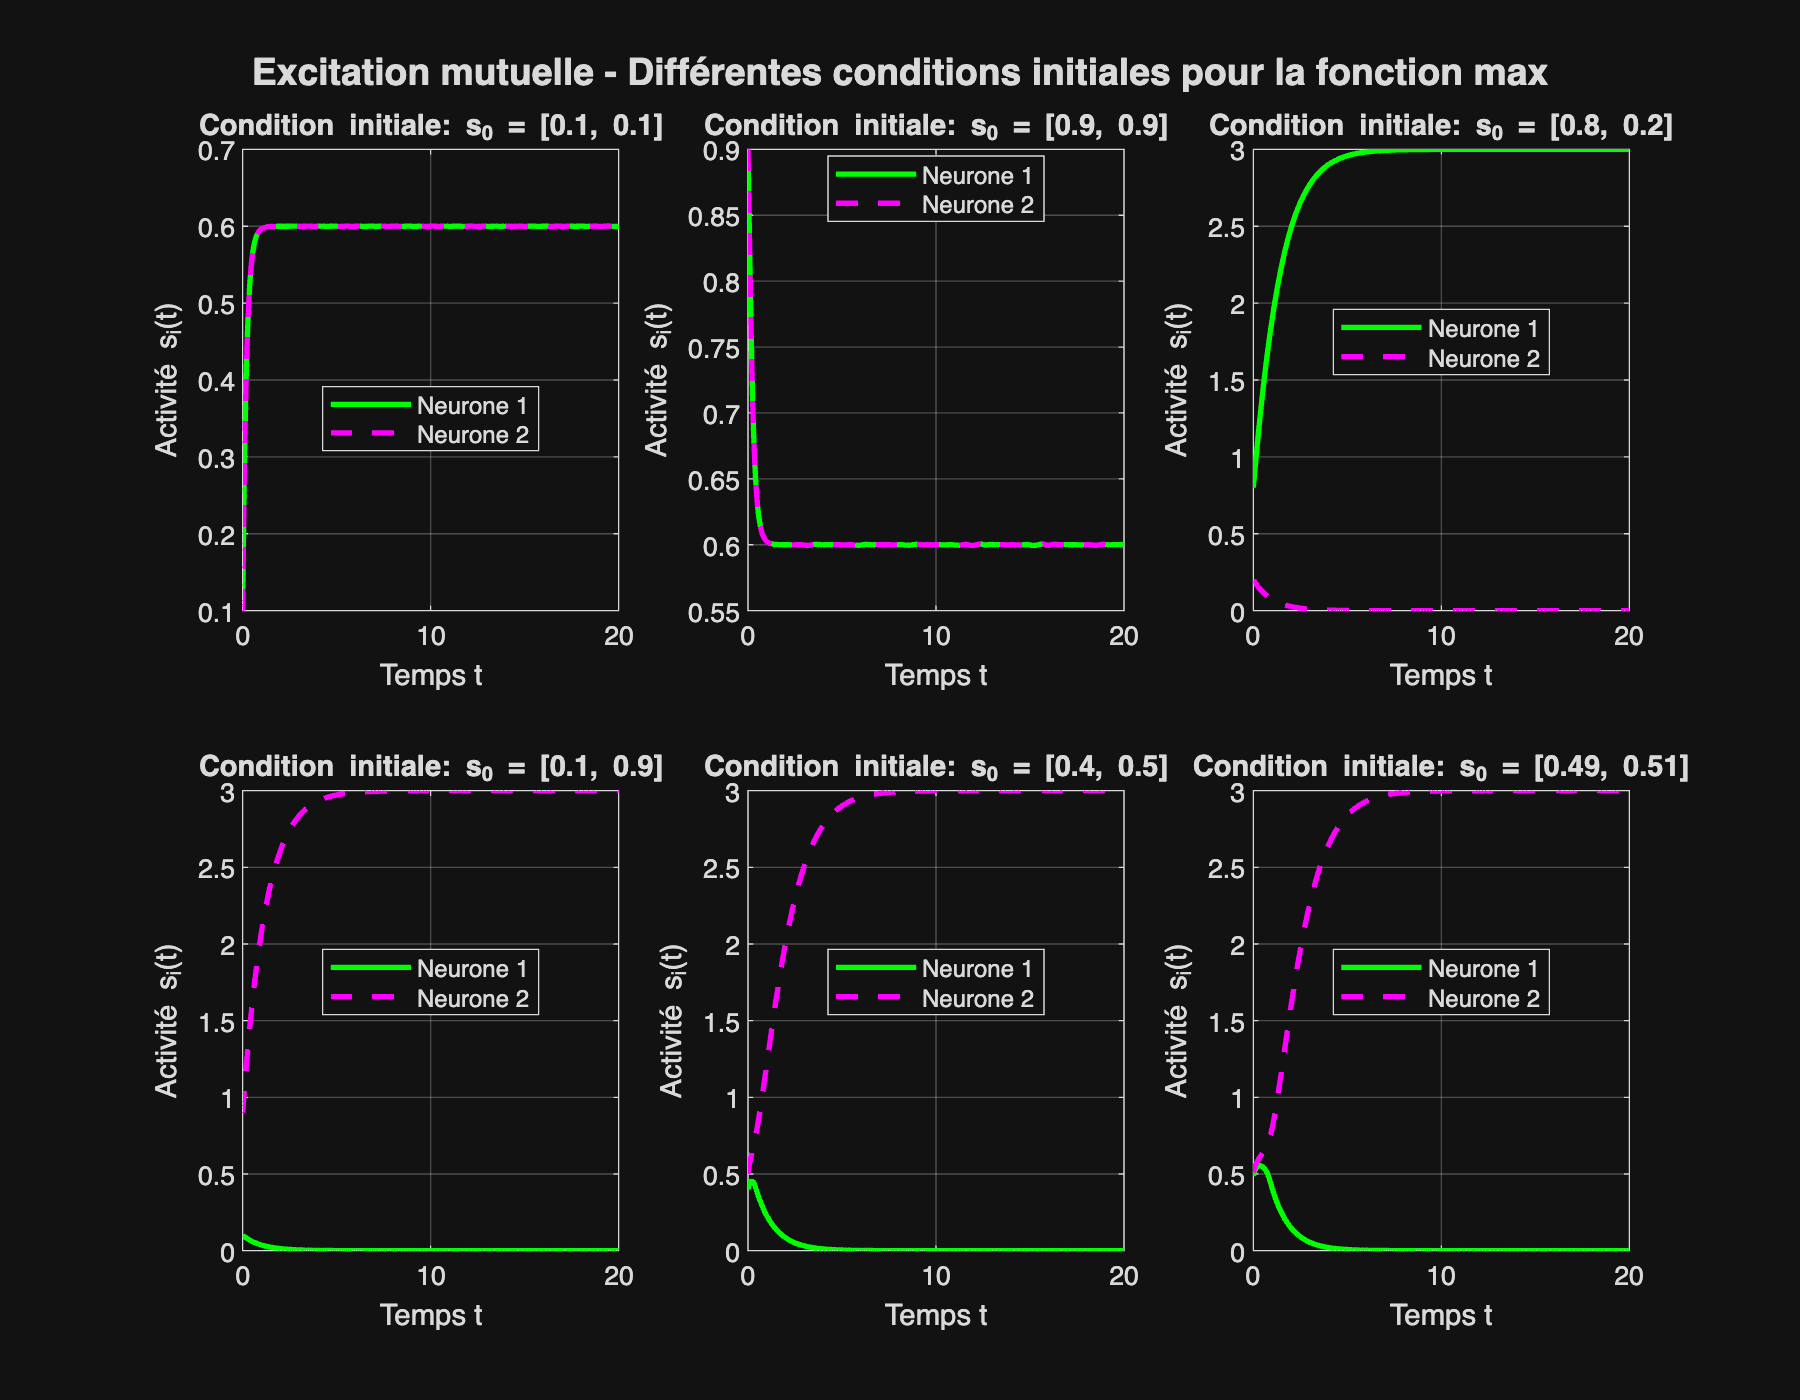

Phi = @(x) max(x, 0);
W = [0, -4; -4, 0];
B = [3; 3];


s0_liste = {[0.1; 0.1],[0.9; 0.9], [0.8; 0.2],  [0.1; 0.9],[0.4,0.5],[0.49,0.51]};
tspan = [0, 20];

figure('Position', [100 100 900 700]);
for k = 1:length(s0_liste)
    s0 = s0_liste{k};
    [t_l, s_l] = ode45(@(t,s) -lambda*s + Phi(W*s + B), tspan, s0);
    

    subplot(2,3,k);
    plot(t_l, s_l(:,1), 'g-', 'LineWidth', 2); hold on;
    plot(t_l, s_l(:,2), 'm--', 'LineWidth', 2);
    xlabel('Temps t', 'FontSize', 11); ylabel('Activité s_i(t)', 'FontSize', 11);
    title(['Condition initiale: s_0 = [' num2str(s0(1)) ', ' num2str(s0(2)) ']'], 'FontSize', 12);
    legend('Neurone 1', 'Neurone 2', 'Location', 'best');
    grid on; set(gca, 'FontSize', 10);
    
end
sgtitle('Excitation mutuelle - Différentes conditions initiales pour la fonction max', 'FontSize', 14, 'FontWeight', 'bold');

Pour $B=\left\lbrack \begin{array}{c}
4\\
4
\end{array}\right\rbrack$ 

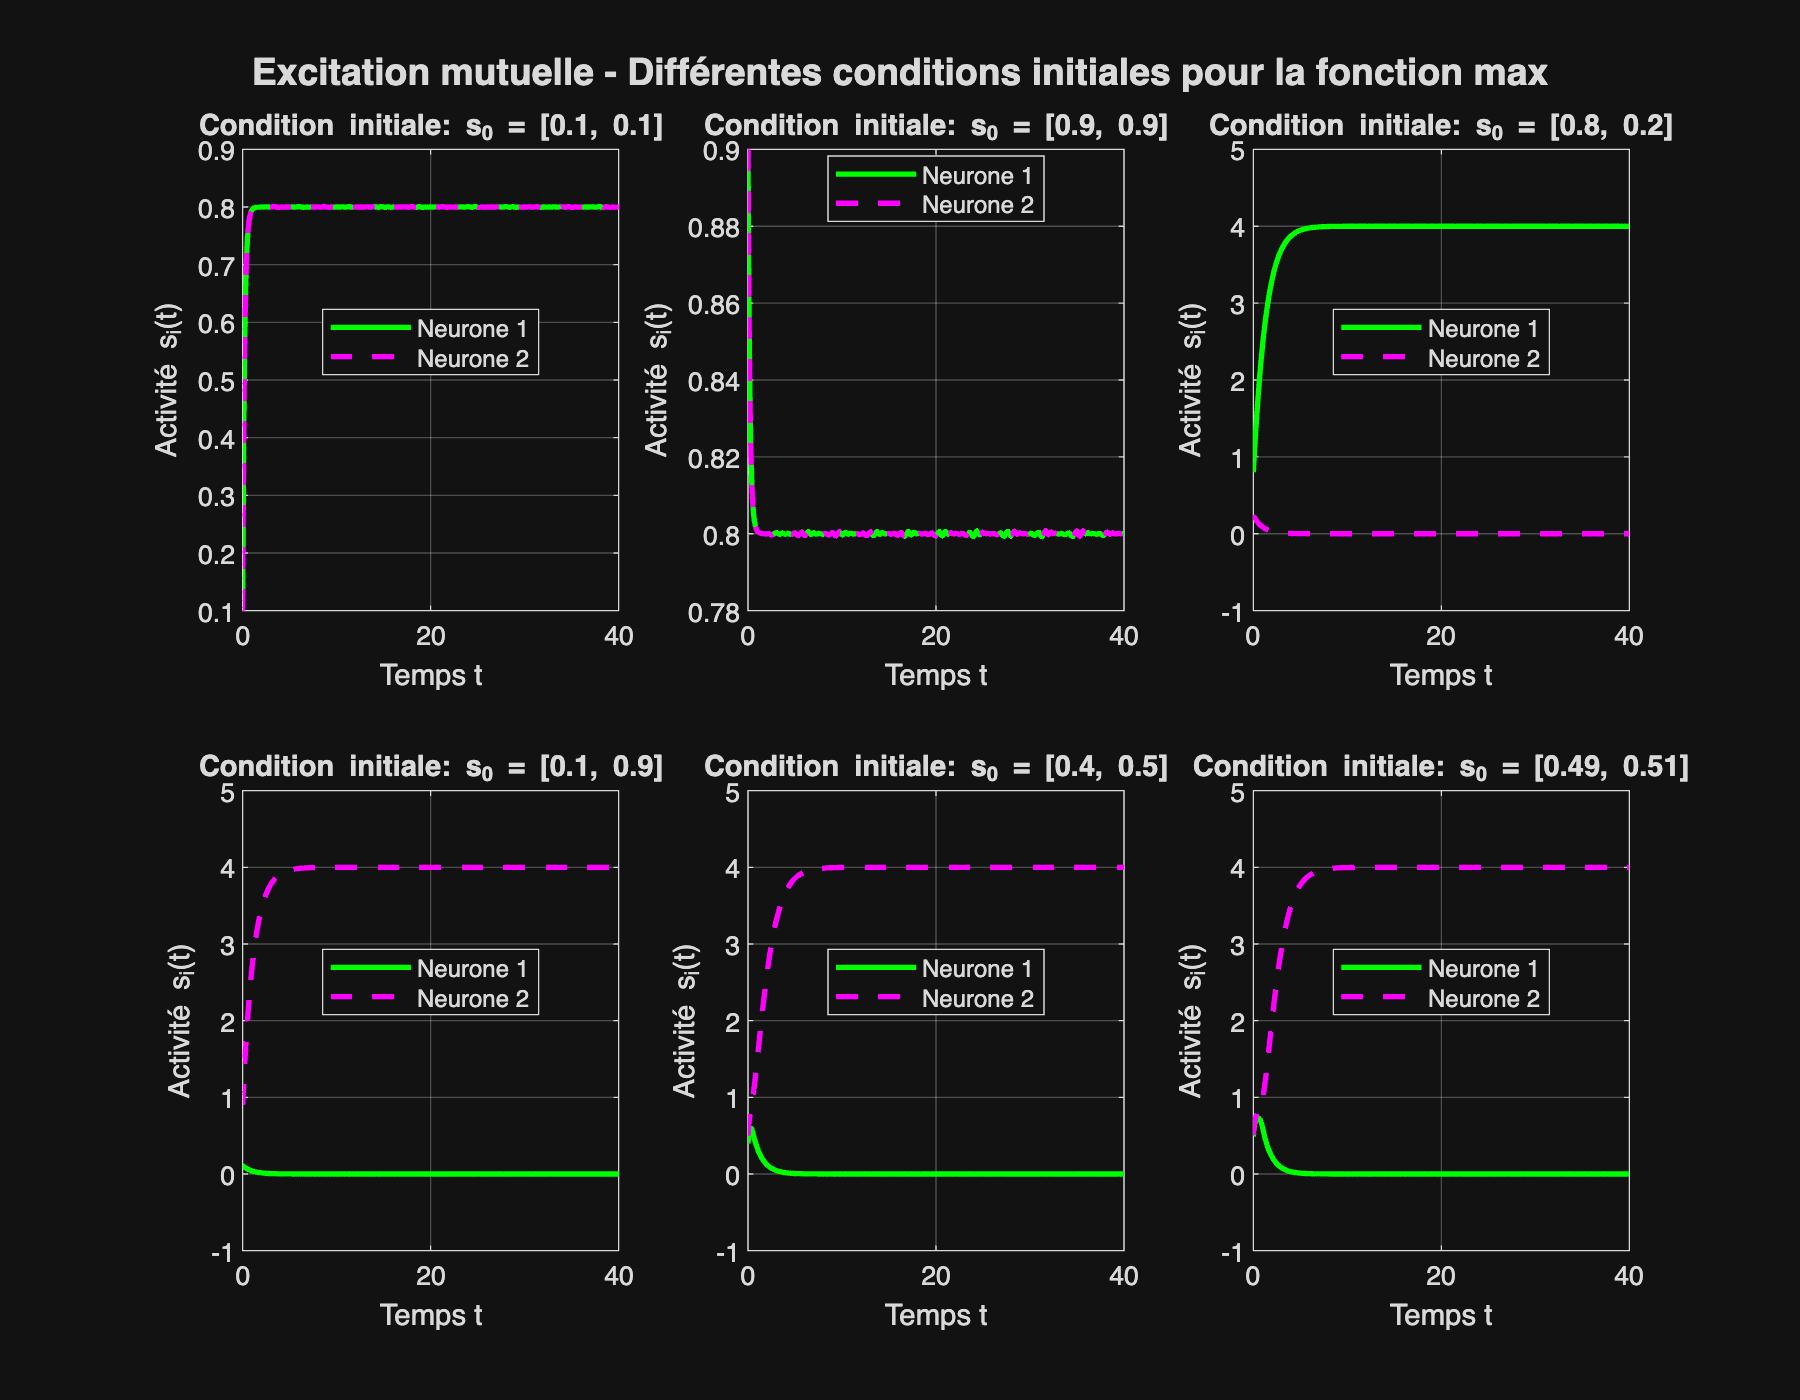

Phi = @(x) max(x, 0);
W = [0, -4; -4, 0];
B = [4; 4];


s0_liste = {[0.1; 0.1],[0.9; 0.9], [0.8; 0.2],  [0.1; 0.9],[0.4,0.5],[0.49,0.51]};
tspan = [0, 40];

figure('Position', [100 100 900 700]);
for k = 1:length(s0_liste)
    s0 = s0_liste{k};
    [t_l, s_l] = ode45(@(t,s) -lambda*s + Phi(W*s + B), tspan, s0);

    subplot(2,3,k);
    plot(t_l, s_l(:,1), 'g-', 'LineWidth', 2); hold on;
    plot(t_l, s_l(:,2), 'm--', 'LineWidth', 2);
    xlabel('Temps t', 'FontSize', 11); ylabel('Activité s_i(t)', 'FontSize', 11);
    title(['Condition initiale: s_0 = [' num2str(s0(1)) ', ' num2str(s0(2)) ']'], 'FontSize', 12);
    legend('Neurone 1', 'Neurone 2', 'Location', 'best');
    grid on; set(gca, 'FontSize', 10);
    
end

sgtitle('Excitation mutuelle - Différentes conditions initiales pour la fonction max', 'FontSize', 14, 'FontWeight', 'bold');

**Observation:** On voit que si on donne la même condition initiale au deux activité elles converge vers la même valeur.

                        Et si à l'origine l'activité 1 est plus grande que l'activité 2 alors l'activité 1 converge vers une valeur supérieur a celle de l'activité 2 l'écart entre les deux valeur diminu quand B augmente

**2) Éxitation asymétrique :**

**Paramètres :**

- $\lambda = 1$ (taux de décroissance)

- $\beta = 2$ (raideur de la logistique)

- $W=\left\lbrack \begin{array}{cc}
0 & -2\\
-10 & 0
\end{array}\right\rbrack$ (excitation mutuelle)

- $B=\left\lbrack \begin{array}{c}
2\\
2
\end{array}\right\rbrack$ (stimulation externe)

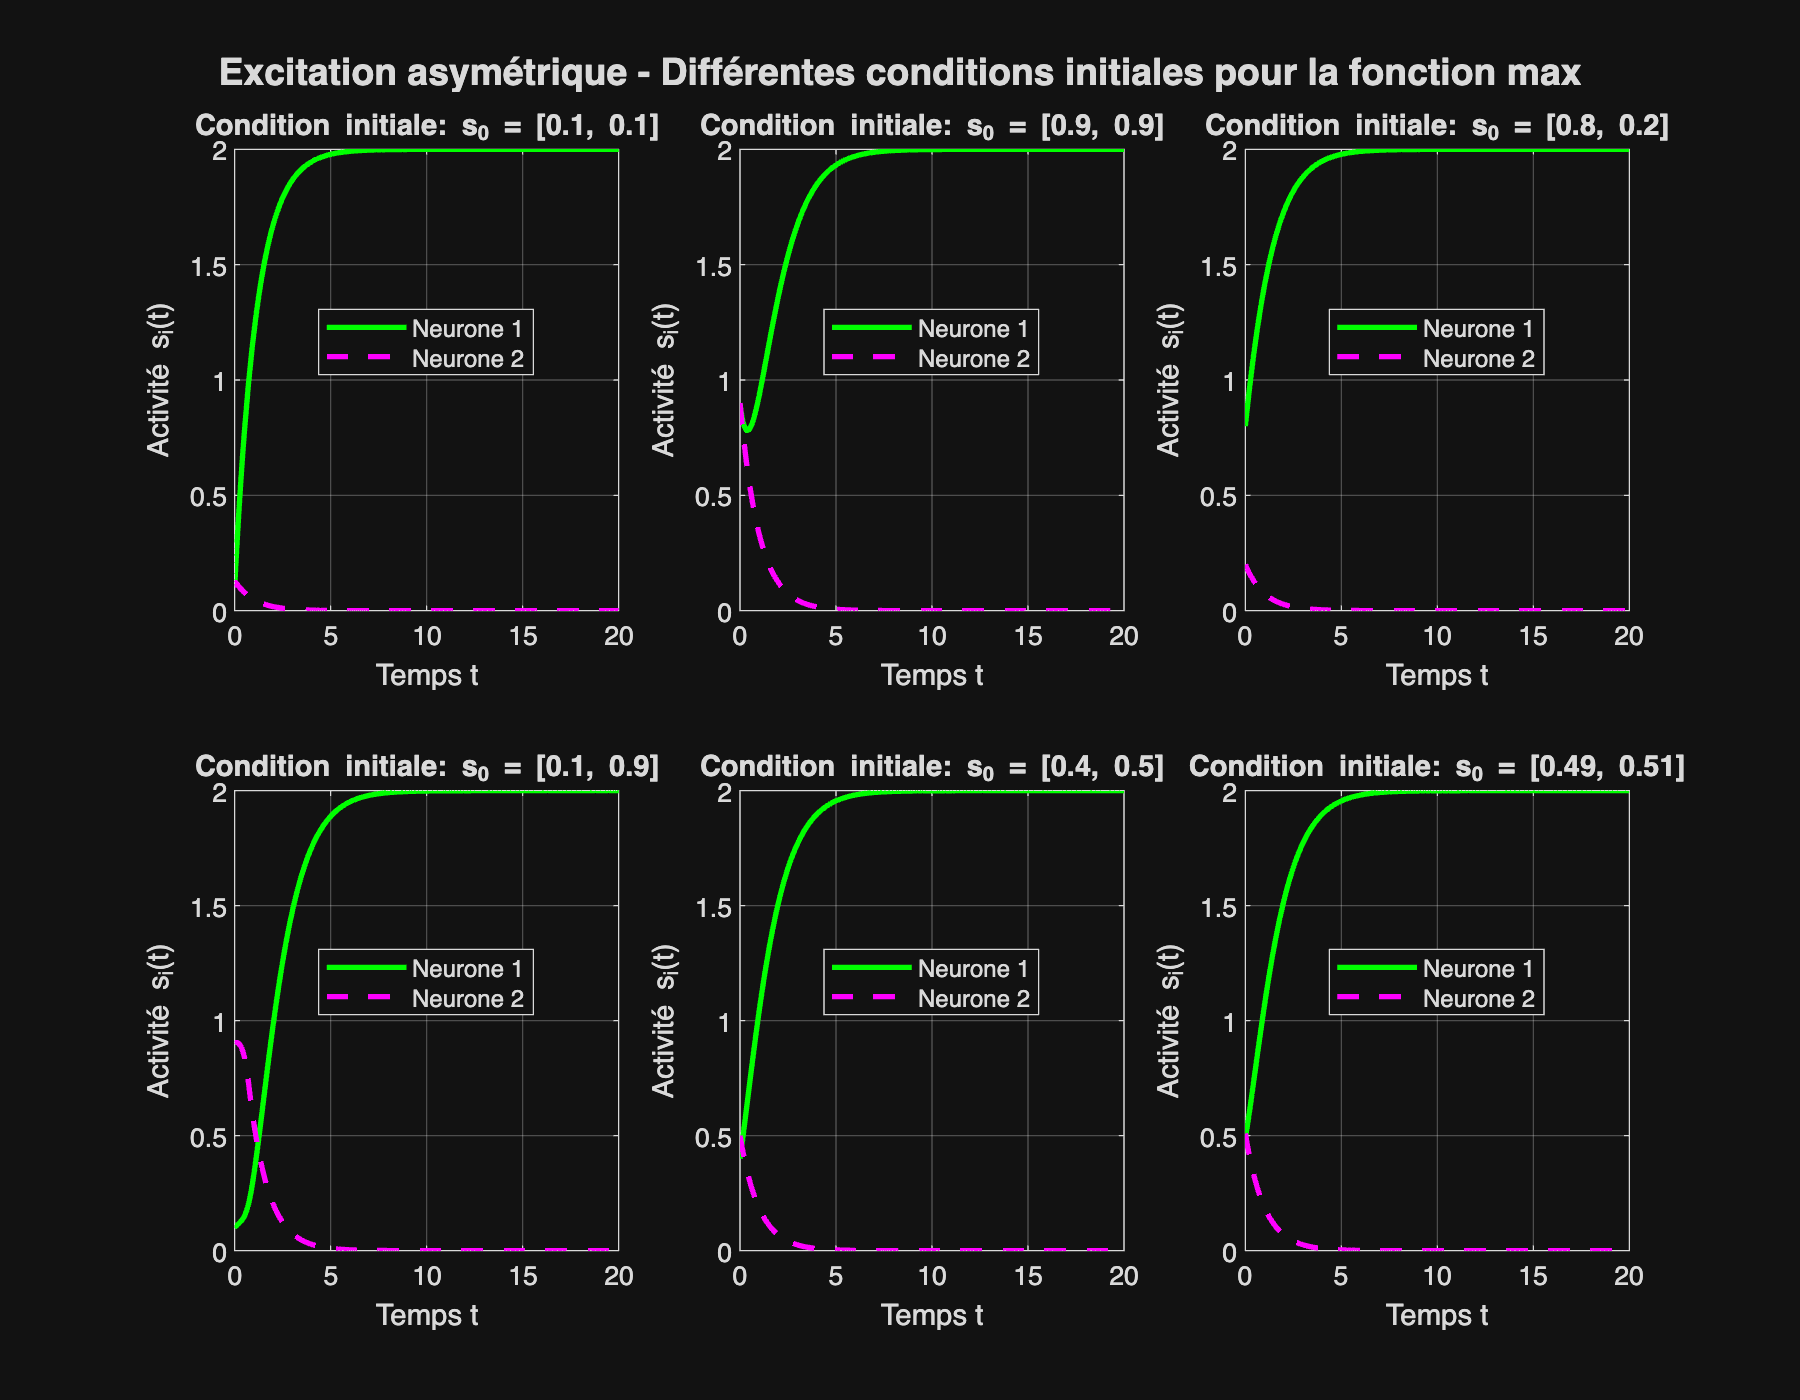

Phi = @(x) max(x, 0);
W = [0,-2; -10, 0];
B = [2; 2];


s0_liste = {[0.1; 0.1],[0.9; 0.9], [0.8; 0.2],  [0.1; 0.9],[0.4,0.5],[0.49,0.51]};
tspan = [0, 20];

figure('Position', [100 100 900 700]);
for k = 1:length(s0_liste)
    s0 = s0_liste{k};
    [t_l, s_l] = ode45(@(t,s) -lambda*s + Phi(W*s + B), tspan, s0);
   

    subplot(2,3,k);
    plot(t_l, s_l(:,1), 'g-', 'LineWidth', 2); hold on;
    plot(t_l, s_l(:,2), 'm--', 'LineWidth', 2);
    xlabel('Temps t', 'FontSize', 11); ylabel('Activité s_i(t)', 'FontSize', 11);
    title(['Condition initiale: s_0 = [' num2str(s0(1)) ', ' num2str(s0(2)) ']'], 'FontSize', 12);
    legend('Neurone 1', 'Neurone 2', 'Location', 'best');
    grid on; set(gca, 'FontSize', 10);
    
end

sgtitle('Excitation asymétrique - Différentes conditions initiales pour la fonction max', 'FontSize', 14, 'FontWeight', 'bold');

Pour $B=\left\lbrack \begin{array}{c}
10\\
10
\end{array}\right\rbrack$ 

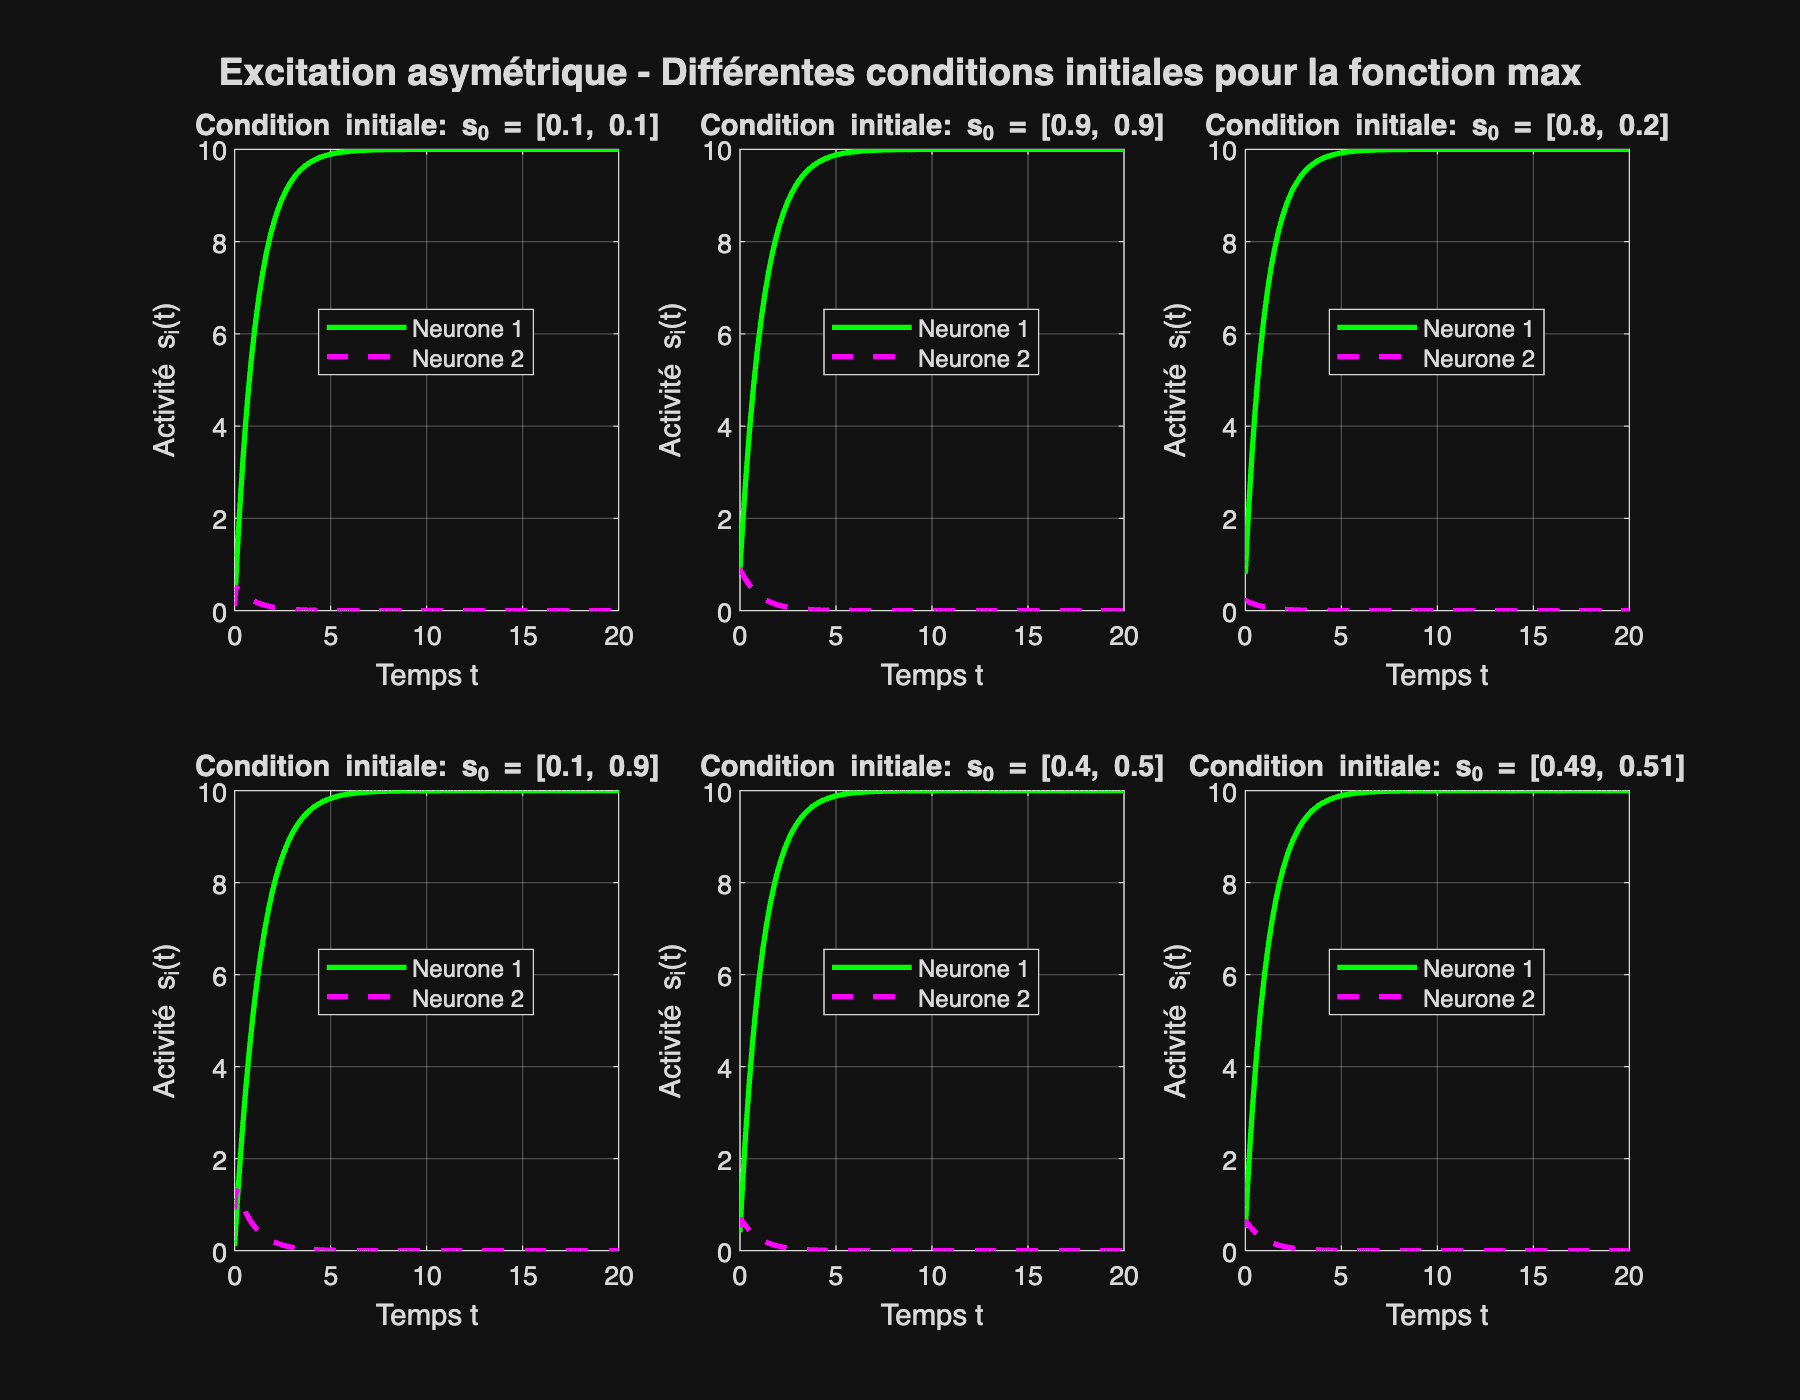

Phi = @(x) max(x, 0);
W = [0,-2; -10, 0];
B = [10; 10];


s0_liste = {[0.1; 0.1],[0.9; 0.9], [0.8; 0.2],  [0.1; 0.9],[0.4,0.5],[0.49,0.51]};
tspan = [0, 20];

figure('Position', [100 100 900 700]);
for k = 1:length(s0_liste)
    s0 = s0_liste{k};
    [t_l, s_l] = ode45(@(t,s) -lambda*s + Phi(W*s + B), tspan, s0);
   

    subplot(2,3,k);
    plot(t_l, s_l(:,1), 'g-', 'LineWidth', 2); hold on;
    plot(t_l, s_l(:,2), 'm--', 'LineWidth', 2);
    xlabel('Temps t', 'FontSize', 11); ylabel('Activité s_i(t)', 'FontSize', 11);
    title(['Condition initiale: s_0 = [' num2str(s0(1)) ', ' num2str(s0(2)) ']'], 'FontSize', 12);
    legend('Neurone 1', 'Neurone 2', 'Location', 'best');
    grid on; set(gca, 'FontSize', 10);
    
end

sgtitle('Excitation asymétrique - Différentes conditions initiales pour la fonction max', 'FontSize', 14, 'FontWeight', 'bold');

**Observation: **On voit dans ce cas ou on a une asymétrie que peux importe les condition initiale le neurone 1 converge vers B est le neurone 2 vers 0, si on augmente B alors le neurone 2 ne converge plus vers 0 mais vers une valeur non nul

**3) Une action positive et une action négative un neurone exitateur est un neurone inibiteur :**

**Paramètres :**

- 
$$\lambda = 1$$
 

- 
$$\beta = 2$$
 

- 
$$W=\left\lbrack \begin{array}{cc}
0 & -4\\
4 & 0
\end{array}\right\rbrack$$
 

- 
$$B=\left\lbrack \begin{array}{c}
2\\
2
\end{array}\right\rbrack$$
 

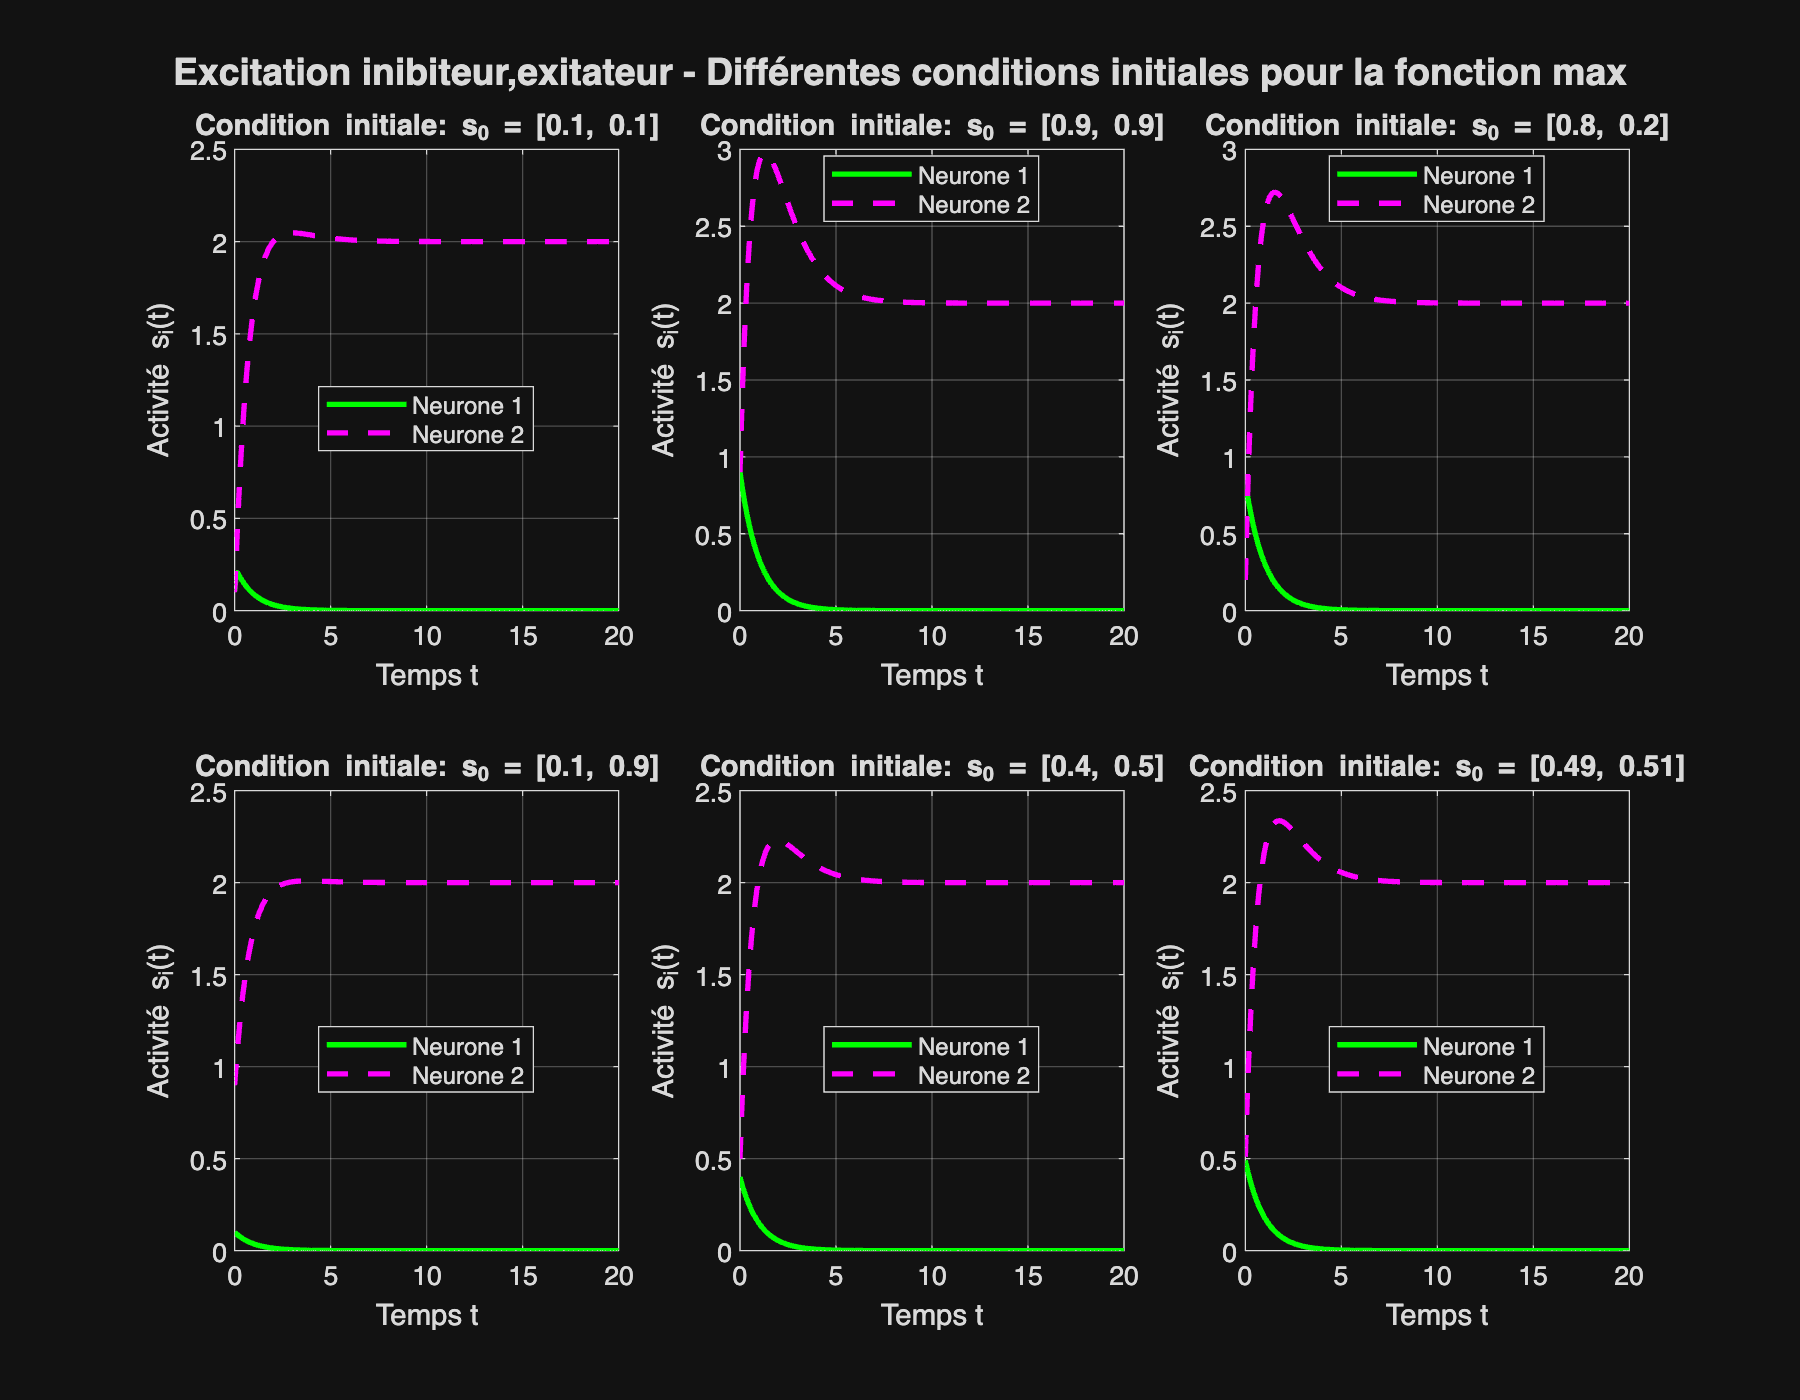

Phi =@(x) max(x, 0);
W = [0,-4; 4, 0];
B = [2; 2];


s0_liste = {[0.1; 0.1],[0.9; 0.9], [0.8; 0.2],  [0.1; 0.9],[0.4,0.5],[0.49,0.51]};
tspan = [0, 20];

figure('Position', [100 100 900 700]);
for k = 1:length(s0_liste)
    s0 = s0_liste{k};
    [t_l, s_l] = ode45(@(t,s) -lambda*s + Phi(W*s + B), tspan, s0);
   

    subplot(2,3,k);
    plot(t_l, s_l(:,1), 'g-', 'LineWidth', 2); hold on;
    plot(t_l, s_l(:,2), 'm--', 'LineWidth', 2);
    xlabel('Temps t', 'FontSize', 11); ylabel('Activité s_i(t)', 'FontSize', 11);
    title(['Condition initiale: s_0 = [' num2str(s0(1)) ', ' num2str(s0(2)) ']'], 'FontSize', 12);
    legend('Neurone 1', 'Neurone 2', 'Location', 'best');
    grid on; set(gca, 'FontSize', 10);
    
end

sgtitle('Excitation inibiteur,exitateur - Différentes conditions initiales pour la fonction max', 'FontSize', 14, 'FontWeight', 'bold');

**Observation : **On voit ici que comme l'action de 2 sur 1 est négative est l'action de 1 sur deux est positive c'est a dire que 1 donne a 2 est 2 prend de 1 alors on a que l'activité de 2 tend vers 2 est l'activité de 1 tend vers 0

## ========================================================================

## QUESTION 2 : Système à n neurones

========================================================================

## 2.1 Stratégies de construction de la matrice W

Quand le nombre de neurones $n$ augmente, on ne peut plus choisir les $n^2$ coefficients manuellement. On utilise des procédures systématiques.

n = 10;
fprintf('Nombre de neurones : n = %d\n\n', n);

Nombre de neurones : n = 10



**Stratégie 1 : Matrice aléatoire normalisée**

On divise par $\sqrt{n}$ car la matrice doit agire comme une isométrie en moyenne

W1 = randn(n, n) / sqrt(n);
fprintf('Stratégie 1 - Norme spectrale : %.3f\n', norm(W1, 2));

Stratégie 1 - Norme spectrale : 1.677


**Stratégie 2 : Connexions locales (structure en anneau)**

Chaque neurone est connecté uniquement à ses $k$ plus proches voisins.

k_voisins = 2;
W2 = zeros(n, n);
for i = 1:n
    for j = -k_voisins:k_voisins
        idx = mod(i - 1 + j, n) + 1;
        if idx ~= i
            W2(i, idx) = 0.5 / (2 * k_voisins);
        end
    end
end
fprintf('Stratégie 2 - Norme spectrale : %.3f\n', norm(W2, 2));

Stratégie 2 - Norme spectrale : 0.500


**Stratégie 3 : Excitateurs (80%) + Inhibiteurs (20%)**

Configuration biologiquement réaliste avec majorité de neurones excitateurs.

n_excit = round(0.8 * n);
W3 = zeros(n, n);
W3(:, 1:n_excit) = abs(randn(n, n_excit)) / sqrt(n);
W3(:, n_excit+1:end) = -abs(randn(n, n - n_excit)) / sqrt(n);
fprintf('Stratégie 3 - Norme spectrale : %.3f\n', norm(W3, 2));

Stratégie 3 - Norme spectrale : 2.679


**Stratégie 4 : Small-world (Watts-Strogatz)**

Connexions locales avec quelques reconnexions aléatoires longue distance.

W4 = W2;
p_rewire = 0.1;
for i = 1:n
    for j = 1:n
        if W4(i,j) ~= 0 && rand < p_rewire
            new_j = randi(n);
            while new_j == i, new_j = randi(n); end
            W4(i, new_j) = W4(i, j); W4(i, j) = 0;
        end
    end
end
fprintf('Stratégie 4 - Norme spectrale : %.3f\n', norm(W4, 2))

Stratégie 4 - Norme spectrale : 0.485


**Stratégie 5 : **

Connexions locales avec 80% d'excitateur est 20% d'inibiteurs



k_voisins = 3;     
ratio_excit = 0.8; 



nb_excit = round(n * ratio_excit);
types_neurones = [ones(1, nb_excit), -ones(1, n - nb_excit)];

types_neurones = types_neurones(randperm(n)); 

W5 = zeros(n, n);


for j = 1:n 
    

    signe = types_neurones(j); 
    
    
    for offset = -k_voisins : k_voisins
        if offset ~= 0 
            
            i = mod(j - 1 + offset, n) + 1;
            
           
            W5(i, j) = signe * abs(randn(1)) * 1/sqrt(n);
        end
    end
end

fprintf('Stratégie 5 - Norme spectrale : %.3f\n', norm(W5,2));

Stratégie 5 - Norme spectrale : 1.880


## 2.2 Visualisation des matrices de connectivité

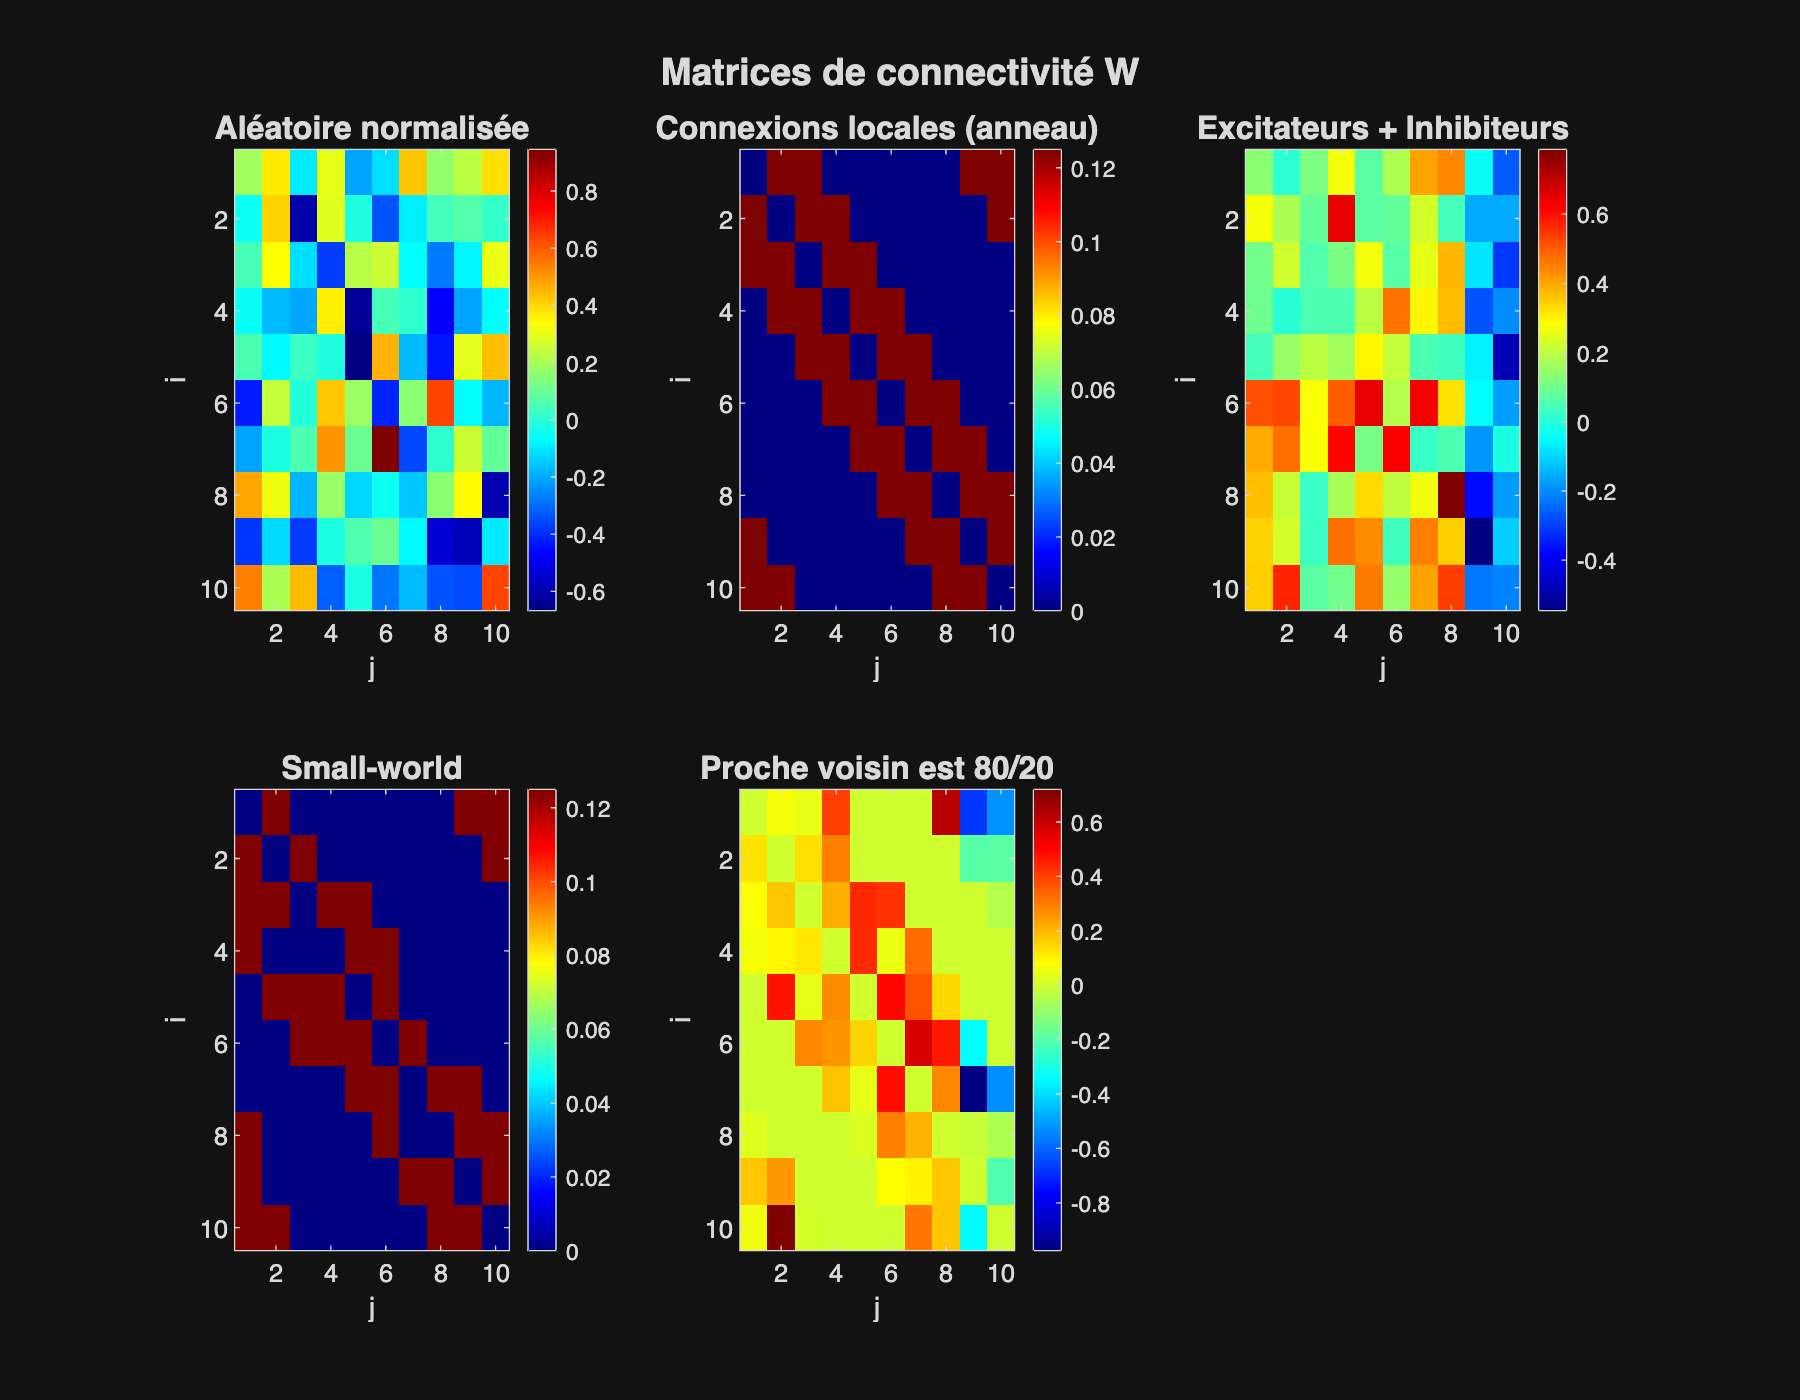

figure('Position', [100 100 900 700]);
subplot(2,3,1); imagesc(W1); colorbar; colormap('jet');
title('Aléatoire normalisée', 'FontSize', 12); xlabel('j'); ylabel('i');
subplot(2,3,2); imagesc(W2); colorbar;
title('Connexions locales (anneau)', 'FontSize', 12); xlabel('j'); ylabel('i');
subplot(2,3,3); imagesc(W3); colorbar;
title('Excitateurs + Inhibiteurs', 'FontSize', 12); xlabel('j'); ylabel('i');
subplot(2,3,4); imagesc(W4); colorbar;
title('Small-world', 'FontSize', 12); xlabel('j'); ylabel('i');
subplot(2,3,5); imagesc(W5); colorbar;
title('Proche voisin est 80/20', 'FontSize', 12); xlabel('j'); ylabel('i');

sgtitle('Matrices de connectivité W', 'FontSize', 14, 'FontWeight', 'bold');

## 2.3 Simulations comparatives

Phi_logistique=@(x, beta) 1 ./ (1 + exp(-beta * x));

Phi = @(x) Phi_logistique(x, 2);
B = ones(n, 1) * 0.5;
s0 = rand(n, 1) * 0.5;
tspan = [0, 30];

figure('Position', [100 100 900 700]);
matrices = {W1, W2, W3, W4,W5};
titres = {'Aléatoire', 'Anneau', 'Excit/Inhib', 'Small-world','Proche voisin est 80/20'};

for k = 1:5
    [t, s] = ode45(@(t,s) -lambda*s + Phi(matrices{k}*s + B), tspan, s0);
    subplot(2,3,k);
    plot(t, s, 'LineWidth', 1);
    xlabel('Temps'); ylabel('Activité s_i(t)');
    title(titres{k}, 'FontSize', 12); ylim([0, 1]); grid on;
end
sgtitle('Évolution temporelle selon le type de connectivité', 'FontSize', 14, 'FontWeight', 'bold');

**Observation :** L'écart-type mesure la désynchronisation entre neurones. Un écart-type qui diminue indique une synchronisation progressive du réseau.

## 2.5 Simulation avec n = 50 neurones

n_grand = 50;
k_voisins = 3;     
ratio_excit = 0.8; 



nb_excit = round(n_grand * ratio_excit);
types_neurones = [ones(1, nb_excit), -ones(1, n_grand - nb_excit)];
types_neurones = types_neurones(randperm(n_grand)); 
W_grand = zeros(n_grand, n_grand);


for j = 1:n_grand
    

    signe = types_neurones(j); 
    
    
    for offset = -k_voisins : k_voisins
        if offset ~= 0 
            
            i = mod(j - 1 + offset, n) + 1;
            
           
            W_grand(i, j) = signe * abs(randn(1)) * 1/sqrt(n_grand);
        end
    end
end




B_grand = ones(n_grand, 1) * 0.5;
s0_grand = rand(n_grand, 1) * 0.5;

[t_g, s_g] = ode45(@(t,s) -lambda*s + Phi(W_grand*s + B_grand), tspan, s0_grand);

figure('Position', [100 100 900 400]);
subplot(1,2,1);
imagesc(t_g, 1:n_grand, s_g'); colorbar; colormap('hot');
xlabel('Temps', 'FontSize', 11); ylabel('Neurone i', 'FontSize', 11);
title('Heatmap de l''activité (n=50)', 'FontSize', 12);

subplot(1,2,2);
plot(t_g, mean(s_g,2), 'b-', 'LineWidth', 2);
xlabel('Temps', 'FontSize', 11); ylabel('Activité moyenne', 'FontSize', 11);
title('Activité moyenne du réseau', 'FontSize', 12); grid on;

## ========================================================================

## QUESTION 3 : Optimisation de la matrice W

========================================================================

## 3.1 Problème d'optimisation

On cherche la matrice $W^*$ qui minimise :


$$H(W) = \int_0^T \left\| -\lambda y(t) + \tilde{\Phi}(Wy(t) + B) - \xi(y(t)) \right\|_2^2 dt$$


où $y(t)$ est la solution cible et $\xi$ est le champ de vecteurs cible.

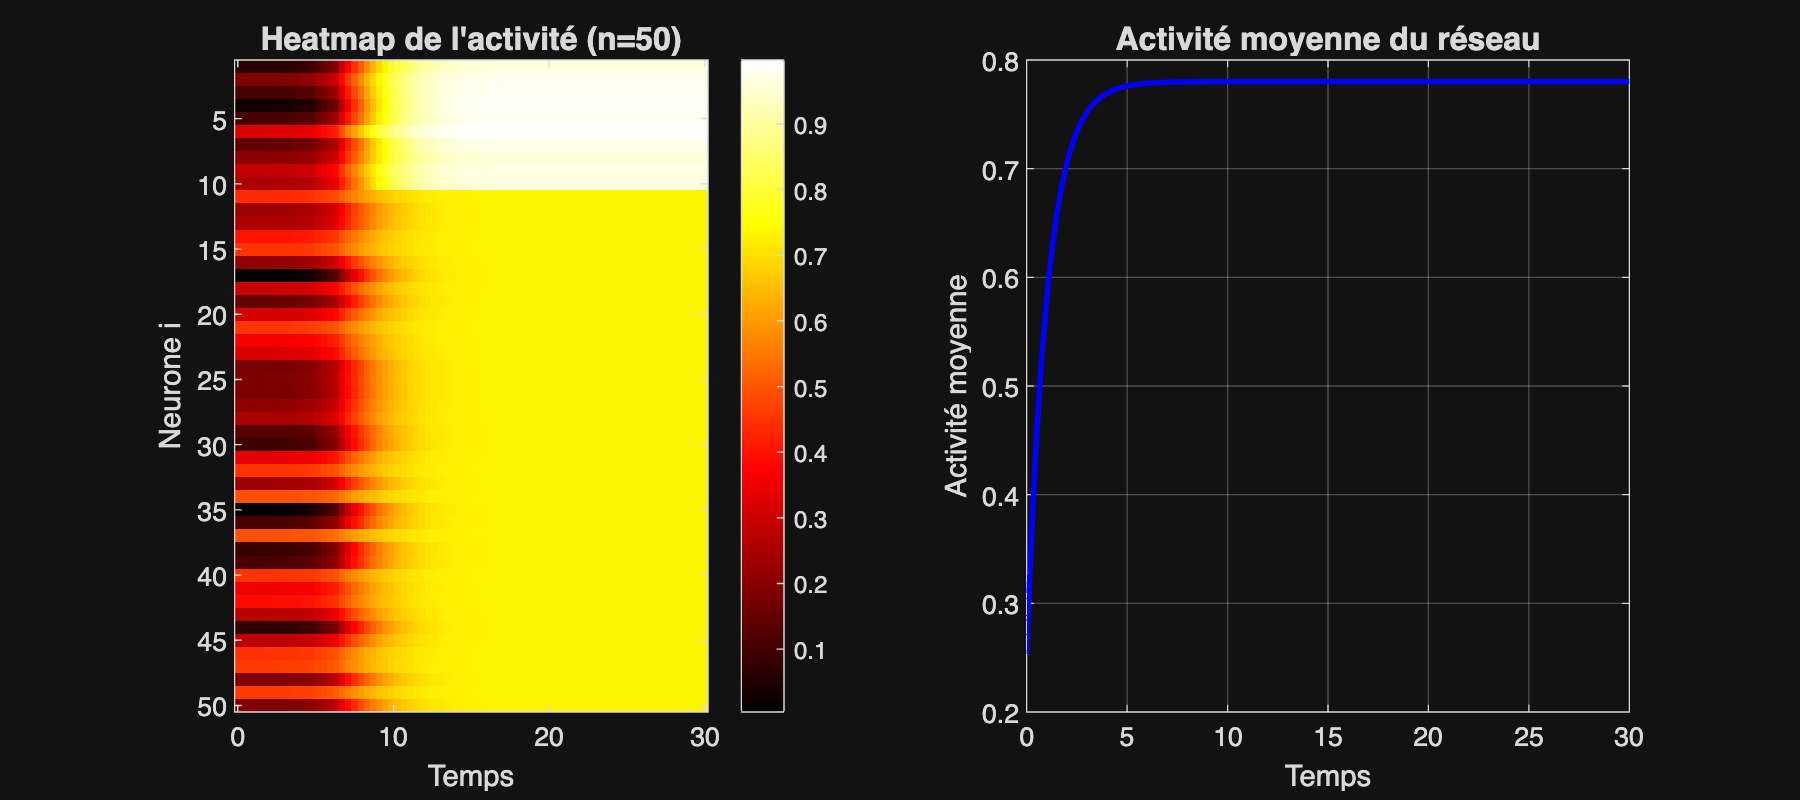

n = 10; T = 5; lambda = 1;
Phi = @(x) 1 ./ (1 + exp(-x));
Phi_deriv = @(x) exp(-x) ./ (1 + exp(-x)).^2;



y0 = zeros(n, 1);
for i = 1:n
    y0(i) = 0.25 * (1 - i / (2*(n-1)));
end


B = zeros(n, 1);
for i = 1:n
    B(i) = 1 + (i-1) / (n-1);
end


R = zeros(n, 1);
for i = 1:n
    R(i) = 9 - 80/n - abs(i - n/2) / n;
end


A = diag(-2*ones(n,1)) + diag(ones(n-1,1), 1) + diag(ones(n-1,1), -1);

## 3.2 Solution cible y(t)

tspan = [0, T];
options = odeset('RelTol', 1e-8, 'AbsTol', 1e-10);
[t_y, y_sol] = ode45(@(t,y) A*y + (R - 0.5*sum(y)).*y, tspan, y0, options);

figure('Position', [100 100 800 500]);
plot(t_y, y_sol, 'LineWidth', 1.5);
xlabel('Temps t', 'FontSize', 12); ylabel('y_i(t)', 'FontSize', 12);
title('Solution cible y(t) du champ \xi', 'FontSize', 14);
legend(arrayfun(@(i) ['y_' num2str(i)], 1:n, 'UniformOutput', false), 'Location', 'eastoutside');
grid on;

## 3.1 Dérivées partielles de H

Les dérivées partielles de $H$ par rapport aux coefficients $w_{ij}$ sont :


$$\frac{\partial H}{\partial w_{ij}} = 2 \int_0^T \left[ \left(-\lambda y + \Phi(Wy+B) - \xi(y)\right)_i \cdot \Phi'((Wy+B)_i) \cdot y_j \right] dt$$


## 3.4 Descente de gradient

On utilise une descente de gradient avec calcul numérique du gradient par différences finies.

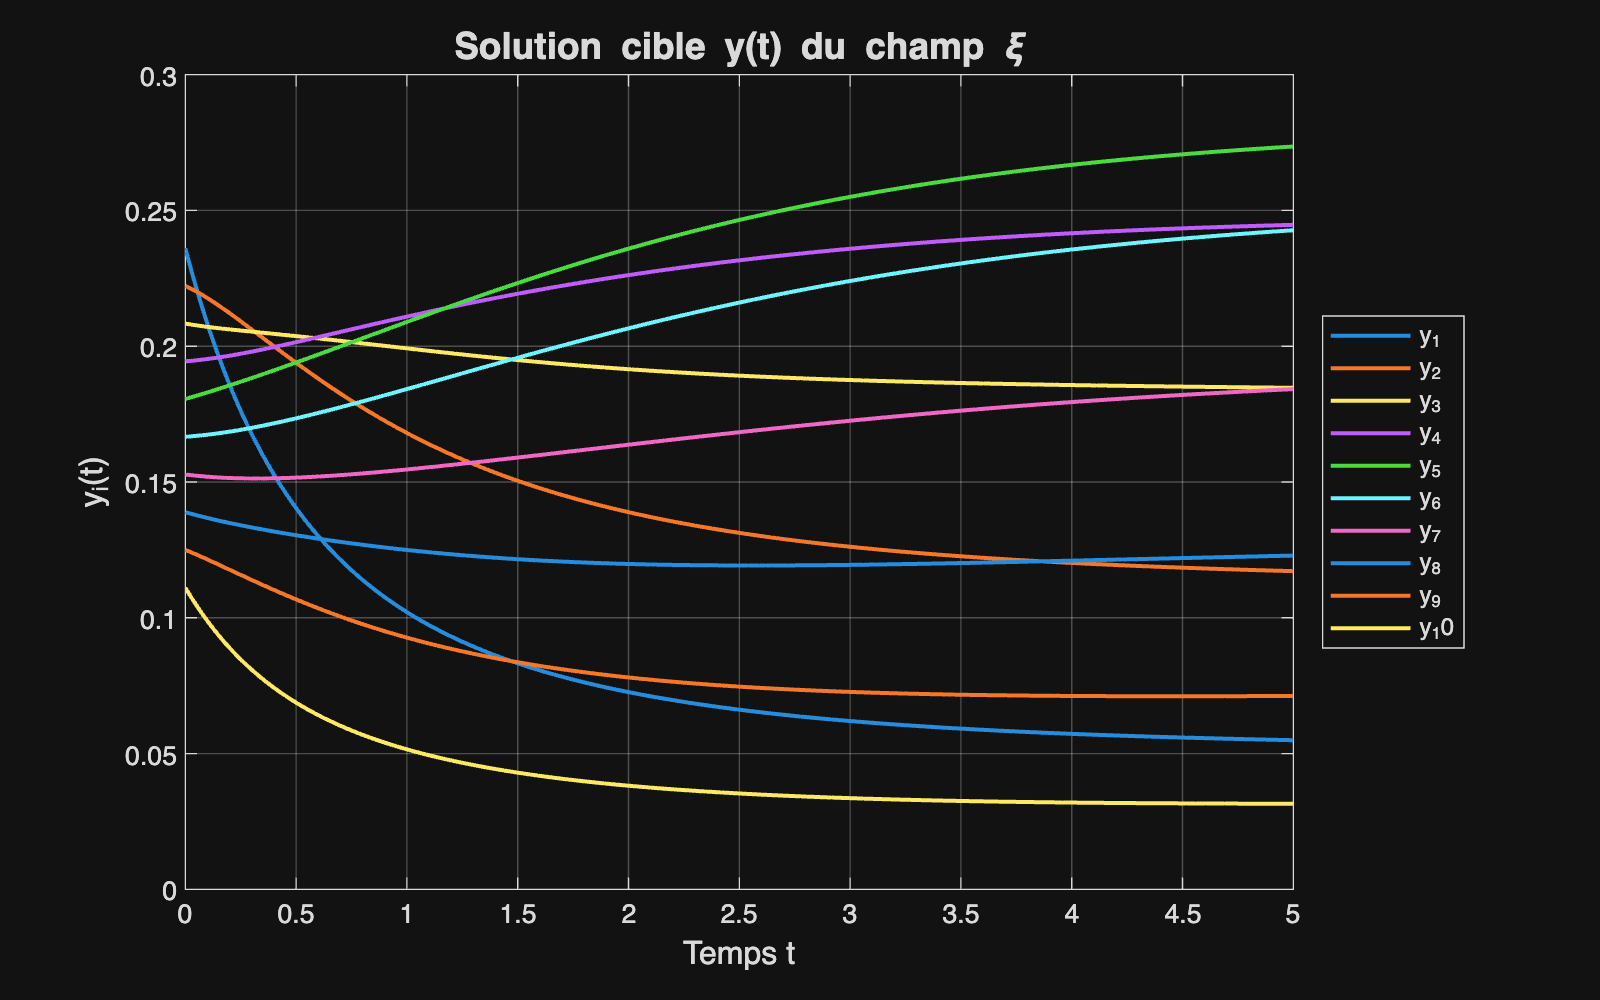

dt = 0.01;              
t_grid = 0:dt:T;        
n_steps = length(t_grid);



Y_target = interp1(t_y, y_sol, t_grid)'; 

Xi_target = zeros(n, n_steps);
for k = 1:n_steps
    y_k = Y_target(:, k);
 
    Xi_target(:, k) = A * y_k + (R - 0.5 * sum(y_k)) .* y_k;

end


W = randn(n, n) * 0.1;  
n_iter = 50000;         
loss_history = zeros(n_iter, 1);
epsilone=0.005

c_armijo = 1e-4;   
rho = 0.5;         
alpha_init = 5.0;  


for k = 1:n_iter
   
    U = W * Y_target + B; 
    Phi_U = Phi(U); 
    E = -lambda * Y_target + Phi_U - Xi_target;
    
    current_loss = sum(sum(E.^2)) * dt;
    loss_history(k) = current_loss;
    

    dPhi_U = Phi_deriv(U);
    Delta = 2 * E .* dPhi_U; 
    Grad_W = (Delta * Y_target') * dt;

epsilone = 0.0050

    
    
    norm_grad_sq = sum(sum(Grad_W.^2));
    

    alpha = alpha_init; 
    found_step = false;
    
    while alpha > 1e-10 
      
        W_try = W - alpha * Grad_W;
        
        
        U_try = W_try * Y_target + B;
        Phi_try = Phi(U_try);
        E_try = -lambda * Y_target + Phi_try - Xi_target;
        loss_try = sum(sum(E_try.^2)) * dt;
        
        %  Condition d'Armijo
       
        target_decrease = c_armijo * alpha * norm_grad_sq;
        
        if loss_try <= current_loss - target_decrease
            
            W = W_try; 
            found_step = true;
            break; 
        else
            alpha = alpha * rho;
        end
    end


  
    if current_loss < epsilone
        
        break;
    end
end

W_opt = W; 


dyn_neuron = @(t, s) -lambda*s + Phi(W*s + B);
[t_s, s_sol] = ode45(dyn_neuron, tspan, y0, options);


figure('Position', [100 100 1000 400]);



neuron_indices = [1,10]; 
hold on;
couleurs = {'b', 'r', 'k'};
for i = 1:length(neuron_indices)
    idx = neuron_indices(i);
    plot(t_y, y_sol(:, idx), '--', 'Color', couleurs{i}, 'LineWidth', 1.5);
    plot(t_s, s_sol(:, idx), '-', 'Color', couleurs{i}, 'LineWidth', 2);
end
title('Comparaison Cible (y) vs Reconstruit (s)');
xlabel('Temps'); ylabel('Activité');
grid on; hold off;

figure;
imagesc(W); colorbar;
title('Matrice de connectivité W^* apprise');
xlabel('Neurone source j'); ylabel('Neurone cible i');
fprintf('Optimisation terminée. H final = %.6f\n', H_hist(end));
imagesc(W_opt); colorbar; colormap('jet');
title('', 'FontSize', 12); xlabel('j'); ylabel('i');

## ========================================================================

## QUESTION 4 : Propagation des incertitudes

========================================================================

## 4.1 Configuration du problème

On étudie un système à 2 neurones avec des conditions initiales incertaines distribuées selon une loi normale.

n = 2; lambda = 1; beta = 2;
Phi = @(x) 1 ./ (1 + exp(-beta * x));
W = [0.5, 1.0; 1.0, 0.5];
B = [0.5; 0.5];
s0_nominal = [0.3; 0.6];
T = 10; tspan = [0, T];

[t_nom, s_nom] = ode45(@(t,s) -lambda*s + Phi(W*s + B), tspan, s0_nominal);

## 4.2 Simulation de Monte Carlo

On calcule la probabilité $P(\|s - s^0\|_{L^2} > \delta)$ par Monte Carlo.

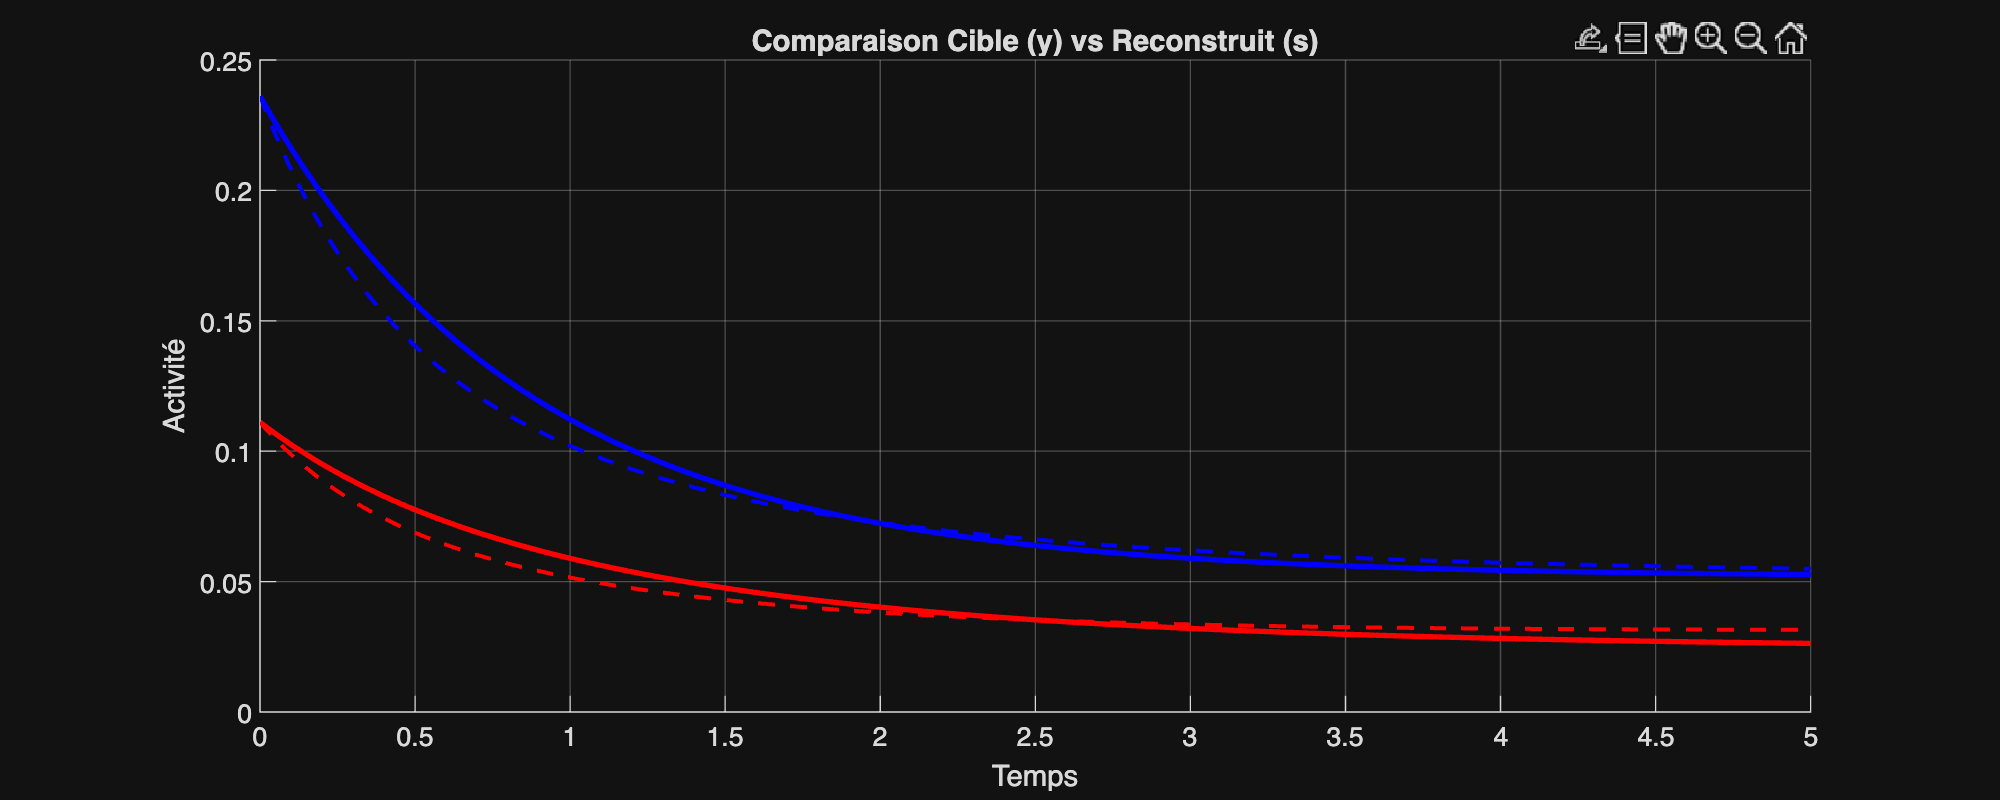

sigma = 0.1;
N_MC = 1000;
delta_values = [0.1, 0.2, 0.3, 0.5];

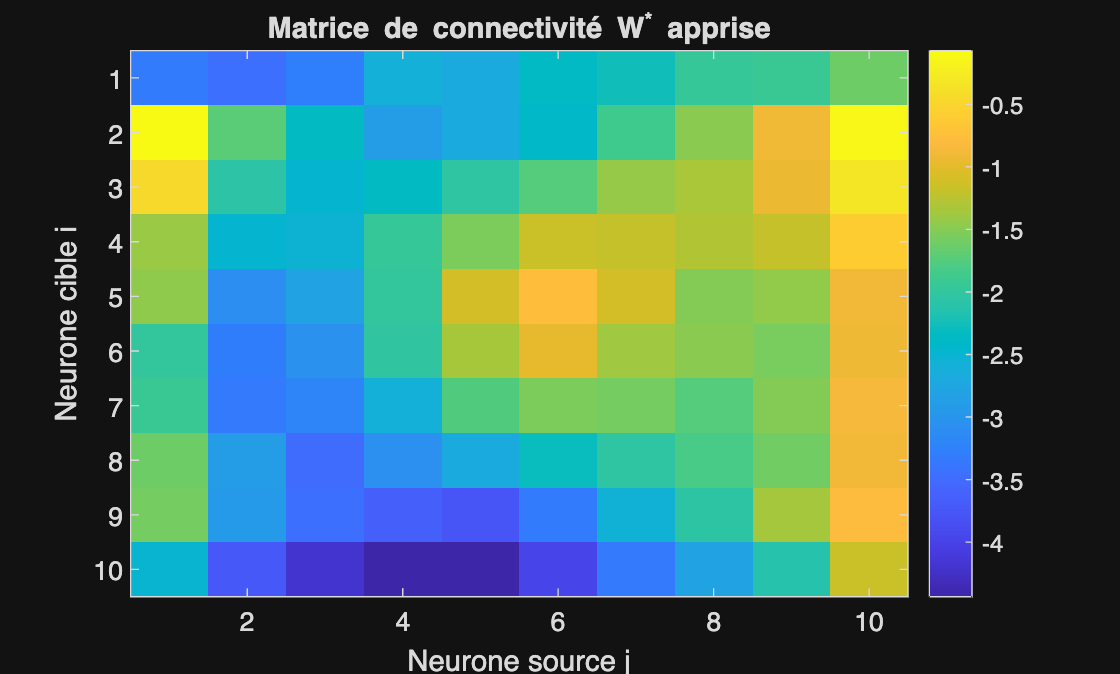




normes_L2 = zeros(N_MC, 1);
for k = 1:N_MC

    s0_pert = s0_nominal + sigma * randn(2, 1);

Optimisation terminée. H final = 0.850876


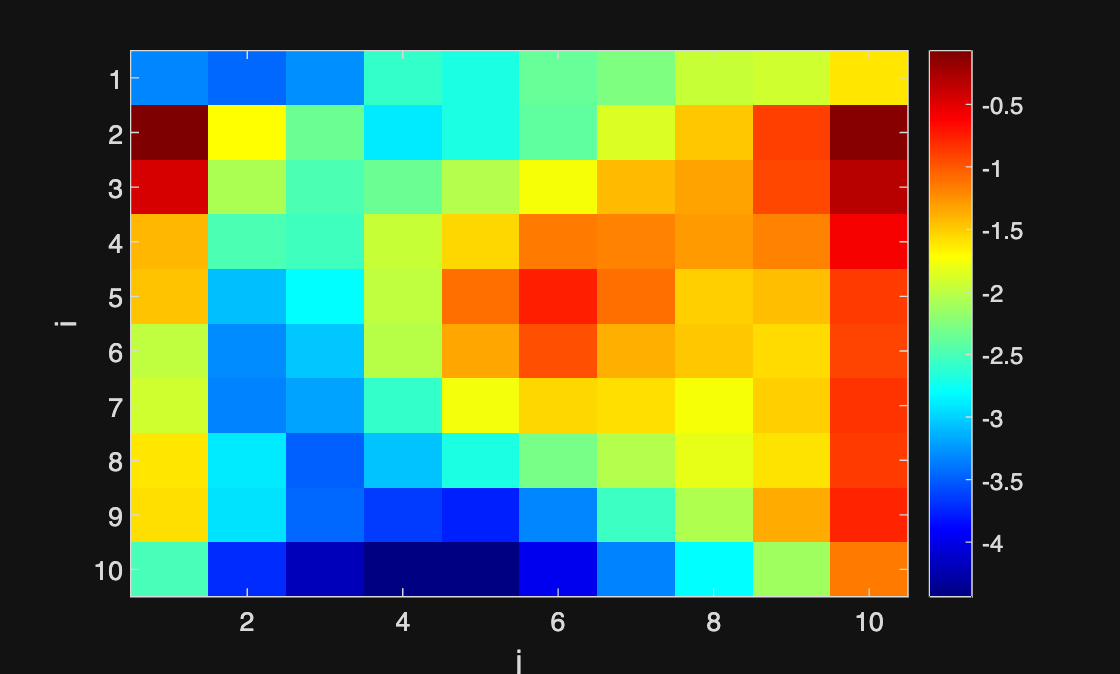

    [t_p, s_p] = ode45(@(t,s) -lambda*s + Phi(W*s + B), tspan, s0_pert);
    s_nom_int = interp1(t_nom, s_nom, t_p);

    
    err = 0;
    for j = 1:length(t_p)-1
        dt = t_p(j+1) - t_p(j);
        d1 = norm(s_p(j,:) - s_nom_int(j,:))^2;
        d2 = norm(s_p(j+1,:) - s_nom_int(j+1,:))^2;
        err = err + dt * (d1 + d2) / 2;
    end
    normes_L2(k) = sqrt(err);
end

## 4.3 Résultats et intervalles de confiance

fprintf('Probabilités estimées :\n');
fprintf('------------------------\n');
proba = zeros(length(delta_values), 1);
IC = zeros(length(delta_values), 2);

for i = 1:length(delta_values)
    delta = delta_values(i);
    p_hat = mean(normes_L2 > delta);
    proba(i) = p_hat;
    std_p = sqrt(p_hat * (1 - p_hat) / N_MC);
    IC(i,:) = [max(0, p_hat - 1.96*std_p), min(1, p_hat + 1.96*std_p)];
    fprintf('  delta = %.2f : P = %.4f, IC_95%% = [%.4f, %.4f]\n', ...
            delta, p_hat, IC(i,1), IC(i,2));
end

figure('Position', [100 100 900 400]);
subplot(1,2,1);
histogram(normes_L2, 30, 'Normalization', 'probability', 'FaceColor', [0.3 0.6 0.9]);
xlabel('||s - s^0||_{L^2}', 'FontSize', 12); ylabel('Probabilité', 'FontSize', 12);
title(['Distribution des erreurs (\sigma=' num2str(sigma) ')'], 'FontSize', 14); grid on;

subplot(1,2,2);
errorbar(delta_values, proba, proba - IC(:,1), IC(:,2) - proba, 'o-', 'LineWidth', 2, 'MarkerSize', 8);
xlabel('\delta', 'FontSize', 12); ylabel('P(||s - s^0||_{L^2} > \delta)', 'FontSize', 12);
title('Probabilité de dépassement du seuil', 'FontSize', 14); grid on;

## 4.4 Recherche de sigma pour P ≤ 10% % On cherche la variance maximale des données d'entrée garantissant que

la norme ne dépasse $\delta$ qu'au plus dans 10% des cas.

delta_cible = 0.3;

Probabilités estimées :


sigma_min = 0.01; sigma_max = 0.5;

------------------------



fprintf('\nRecherche de sigma pour P(||s-s^0|| > %.1f) <= 10%%\n', delta_cible);

while sigma_max - sigma_min > 0.01
    sigma_test = (sigma_min + sigma_max) / 2;
    compteur = 0;
    for k = 1:500
        s0_p = s0_nominal + sigma_test * randn(2, 1);
        [t_p, s_p] = ode45(@(t,s) -lambda*s + Phi(W*s + B), tspan, s0_p);
        s_nom_int = interp1(t_nom, s_nom, t_p);
        err = 0;
        for j = 1:length(t_p)-1

  delta = 0.10 : P = 0.3930, IC_95% = [0.3627, 0.4233]
  delta = 0.20 : P = 0.0200, IC_95% = [0.0113, 0.0287]
  delta = 0.30 : P = 0.0000, IC_95% = [0.0000, 0.0000]
  delta = 0.50 : P = 0.0000, IC_95% = [0.0000, 0.0000]


            dt = t_p(j+1) - t_p(j);
            err = err + dt * (norm(s_p(j,:)-s_nom_int(j,:))^2 + norm(s_p(j+1,:)-s_nom_int(j+1,:))^2)/2;
        end
        if sqrt(err) > delta_cible, compteur = compteur + 1; end
    end
    p_est = compteur / 500;
    if p_est > 0.10, sigma_max = sigma_test; else, sigma_min = sigma_test; end
end
sigma_opt = (sigma_min + sigma_max) / 2;
fprintf('=> sigma maximal : %.4f\n', sigma_opt);

## 4.5 Visualisation de l'effet de sigma sur les trajectoires

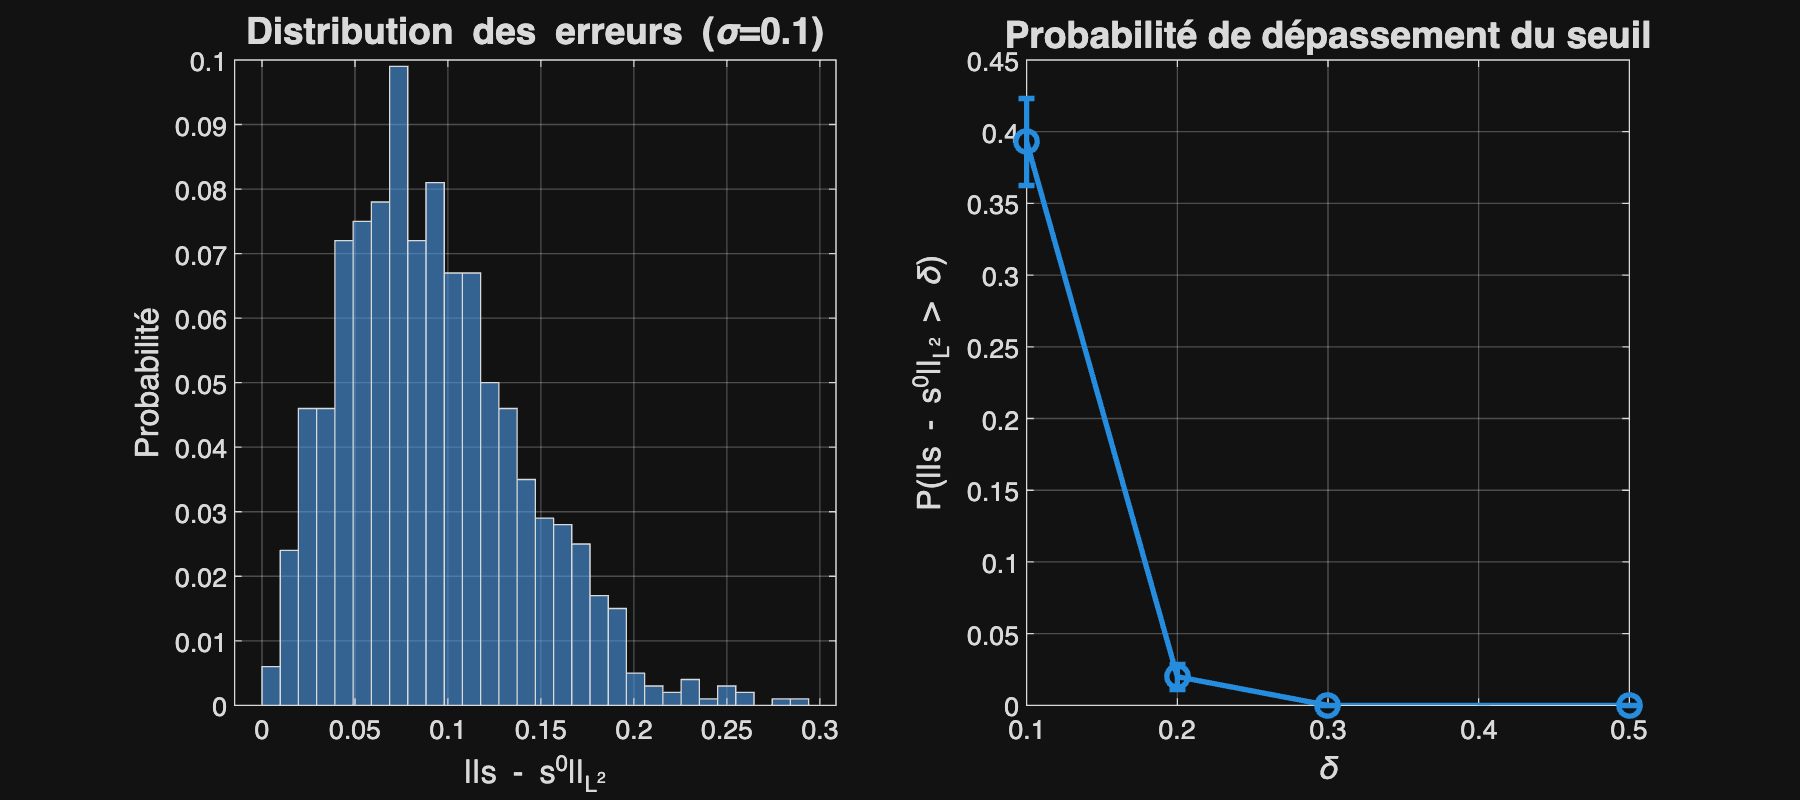

figure('Position', [100 100 900 700]);

sigma_range = [0.05, 0.1, 0.15, 0.2];
for idx = 1:4
    sig = sigma_range(idx);
    subplot(2,2,idx); hold on;
    for k = 1:20
        s0_p = s0_nominal + sig * randn(2, 1);
        [t_p, s_p] = ode45(@(t,s) -lambda*s + Phi(W*s + B), tspan, s0_p);


Recherche de sigma pour P(||s-s^0|| > 0.3) <= 10%


        plot(s_p(:,1), s_p(:,2), 'Color', [0.7 0.7 0.7], 'LineWidth', 0.5);
    end
    plot(s_nom(:,1), s_nom(:,2), 'b-', 'LineWidth', 2);
    plot(s0_nominal(1), s0_nominal(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
    xlabel('s_1'); ylabel('s_2');
    title(['\sigma = ' num2str(sig)], 'FontSize', 12); grid on;
end
sgtitle('Effet de l''incertitude sur les trajectoires', 'FontSize', 14, 'FontWeight', 'bold');

## ========================================================================

## QUESTION 5 : Gradient stochastique

========================================================================

n = 10; 
T = 5; 

=> sigma maximal : 0.1899


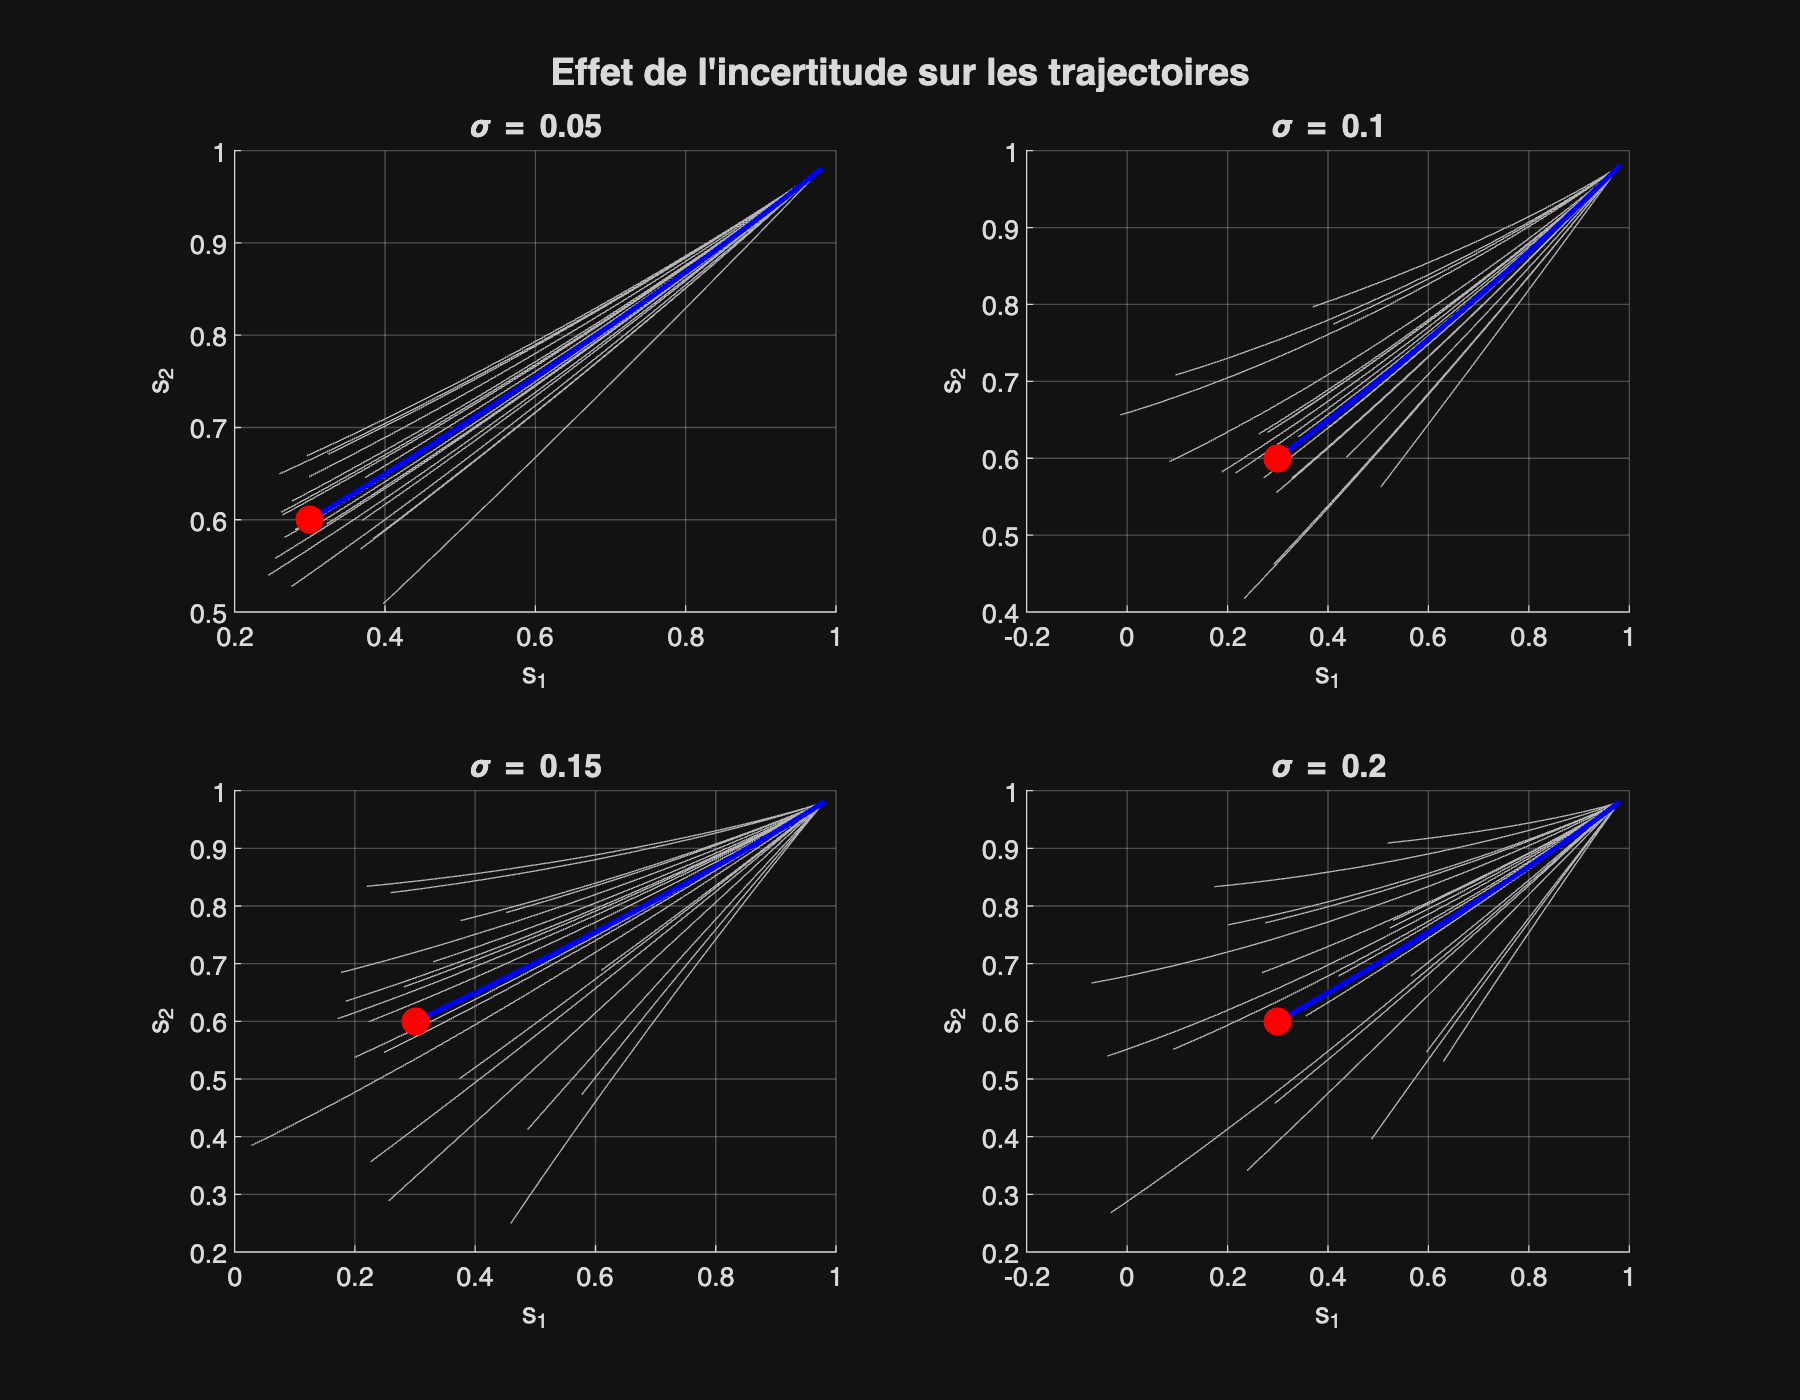

lambda = 1;


phi = @(x) 1 ./ (1 + exp(-x));
phi_deriv = @(x) exp(-x) ./ (1 + exp(-x)).^2;

y0 = zeros(n, 1);
for i = 1:n
    y0(i) = 0.25 * (1 - i / (2*(n-1)));
end

B_mean = zeros(n, 1); 
for i = 1:n
    B_mean(i) = 1 + (i-1) / (n-1);
end

R = zeros(n, 1);
for i = 1:n

Iter 1: Loss = 20.3970 | Gamma = 1.0000
Iter 100: Loss = 7.9463 | Gamma = 0.0100
Iter 200: Loss = 6.4288 | Gamma = 0.0050
Iter 300: Loss = 5.6721 | Gamma = 0.0033
Iter 400: Loss = 5.1781 | Gamma = 0.0025
Iter 500: Loss = 4.8305 | Gamma = 0.0020
Iter 600: Loss = 4.5637 | Gamma = 0.0017
Iter 700: Loss = 4.3466 | Gamma = 0.0014
Iter 800: Loss = 4.1689 | Gamma = 0.0013
Iter 900: Loss = 4.0195 | Gamma = 0.0011
Iter 1000: Loss = 3.8918 | Gamma = 0.0010
Iter 1100: Loss = 3.7764 | Gamma = 0.0009
Iter 1200: Loss = 3.6769 | Gamma = 0.0008
Iter 1300: Loss = 3.5873 | Gamma = 0.0008
Iter 1400: Loss = 3.5062 | Gamma = 0.0007
Iter 1500: Loss = 3.4326 | Gamma = 0.0007
Iter 1600: Loss = 3.3647 | Gamma = 0.0006
Iter 1700: Loss = 3.3021 | Gamma = 0.0006
Iter 1800: Loss = 3.2461 | Gamma = 0.0006
Iter 1900: Loss = 3.1928 | Gamma = 0.0005
Iter 2000: Loss = 3.1418 | Gamma = 0.0005


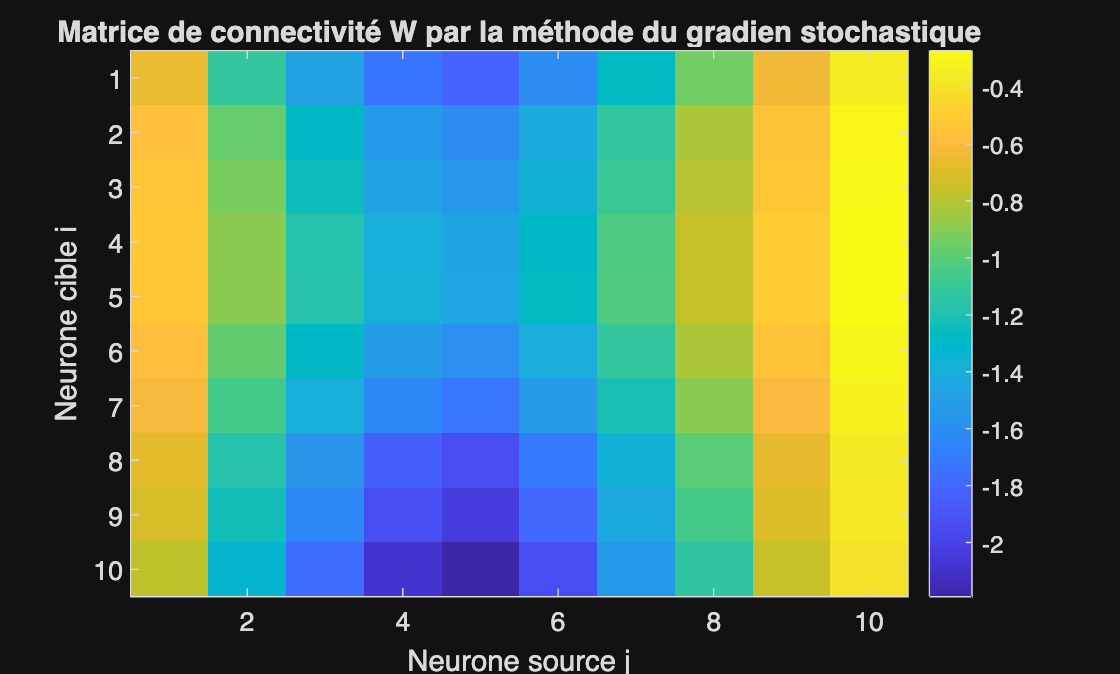

W =    -0.6605   -1.1163   -1.4732   -1.7310   -1.8183   -1.6063   -1.2793   -0.9435   -0.6351   -0.3415
   -0.5570   -0.9644   -1.2888   -1.5249   -1.6068   -1.4185   -1.1258   -0.8250   -0.5494   -0.2896
   -0.5404   -0.9303   -1.2399   -1.4649   -1.5426   -1.3620   -1.0818   -0.7937   -0.5298   -0.2806
   -0.5246   -0.8932   -1.1821   -1.3907   -1.4615   -1.2908   -1.0274   -0.7567   -0.5082   -0.2716
   -0.5273   -0.8923   -1.1758   -1.3793   -1.4476   -1.2786   -1.0191   -0.7526   -0.5073   -0.2725
   -0.5760   -0.9759   -1.2868   -1.5103   -1.5854   -1.4004   -1.1158   -0.8237   -0.5548   -0.2978
   -0.6156   -1.0500   -1.3910   -1.6372   -1.7210   -1.5199   -1.2094   -0.8904   -0.5975   -0.3188
   -0.6834   -1.1727   -1.5597   -1.8404   -1.9368   -1.7103   -1.3592   -0.9985   -0.6677   -0.3545
   -0.7150   -1.2302   -1.6387   -1.9356   -2.0380   -1.7995   -1.4294   -1.0491   -0.7006   -0.3712
   -0.7777   -1.3294   -1.7655   -2.0819   -2.1905   -1.9345   -1.5380   -1.1305   -0.7

    R(i) = 9 - 80/n - abs(i - n/2) / n;
end


A = diag(-2*ones(n,1)) + diag(ones(n-1,1), 1) + diag(ones(n-1,1), -1);


xi_fun = @(y) A*y + (R - 0.5*sum(y)).*y;


options = odeset('RelTol', 1e-8, 'AbsTol', 1e-10);
[t_out, y_out] = ode45(@(t,y) xi_fun(y), [0, T], y0, options);

dt = 0.05;
t_span = 0:dt:T;
n_steps = length(t_span);

Y_target = interp1(t_out, y_out, t_span)'; 

Xi_vals = zeros(n, n_steps);
for k = 1:n_steps
    Xi_vals(:, k) = xi_fun(Y_target(:, k));
end

drawnow;


K_iter = 2000;          
sigma_B = 0.5;          % Incertitude sur B


W = zeros(n, n); 
loss_history = zeros(K_iter, 1);



for k = 1:K_iter
    
    mu = 1.0; 
    gamma_k = mu / k;
    
    
    B_k = B_mean + sigma_B * randn(n, 1);
    

    U = W * Y_target + repmat(B_k, 1, n_steps);
    
    Phi_U = phi(U);
    dPhi_U = phi_deriv(U); 
    
    Error = -lambda * Y_target + Phi_U - Xi_vals;
    
   
    Term_A = 2 * Error .* dPhi_U;
    Grad_W = (Term_A * Y_target') * dt;
    
    
    W = W - gamma_k * Grad_W;
    
   
    if mod(k, 100) == 0 || k == 1
       
        U_mean = W * Y_target + repmat(B_mean, 1, n_steps);
        Err_mean = -lambda * Y_target + phi(U_mean) - Xi_vals;
        loss = sum(sum(Err_mean.^2)) * dt;
        loss_history(k) = loss;
        fprintf('Iter %d: Loss = %.4f | Gamma = %.4f\n', k, loss, gamma_k);
    else
        loss_history(k) = loss_history(k-1);
    end
end

figure;
imagesc(W); colorbar;
title('Matrice de connectivité W par la méthode du gradien stochastique');
xlabel('Neurone source j'); ylabel('Neurone cible i');
title('Matrice de connectivité W par la méthode du gradien stochastique');
W